## Task 1

## mDH table

close all; clear; clc;

% for saving figures

global file_format;
file_format = ".png";

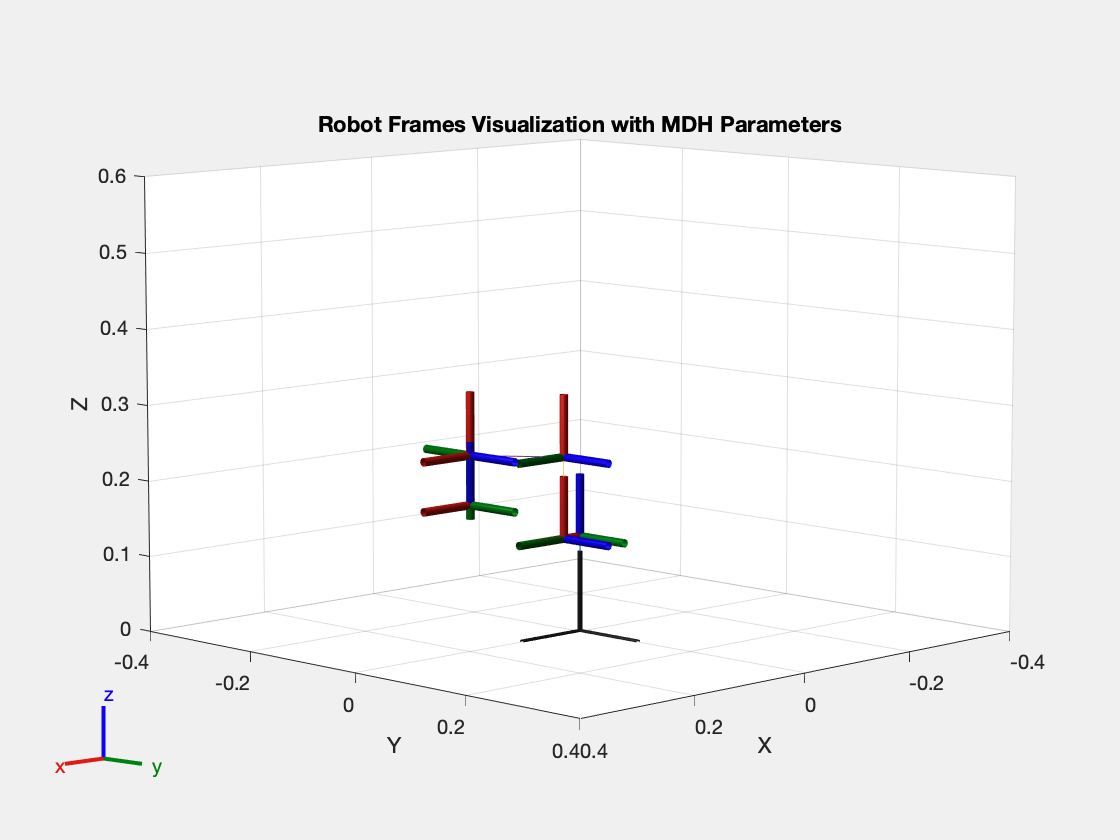

l1 = 127.00 / 1000;
l2 = 29.69 / 1000;
l3 = 108.00 / 1000;
l4 = 20.00 / 1000;
l5 = 168.98 / 1000;
l6 = (24.29 + 40.00) / 1000;

l7 = 25.00 / 1000;
l8 = 27.50 / 1000;
l9 = 40.00 / 1000;

dhparams = [
    0 0 l1 0;
    l2 -pi/2 0 0;
    l3 0 0 0;
    l4 -pi/2 l5 0;
    0 pi/2 0 0;
    0 pi/2 -l6 0;
];

% bonus task
if false
    dhparams(6, :) = [l8 pi/2 -(l7 + l9) 0];
end

home_joint_angles = [0 -pi/2 0 0 pi/2 0];

robot = rigidBodyTree('DataFormat','column');

base = rigidBody('base');
part1 = rigidBody('part1');
part2 = rigidBody('part2');
part3 = rigidBody('part3');
part4 = rigidBody('part4');
part5 = rigidBody('part5');
endeffector = rigidBody('endeffector');

jnt1 = rigidBodyJoint('jnt1', 'revolute');
jnt1.HomePosition = home_joint_angles(1);

jnt2 = rigidBodyJoint('jnt2', 'revolute');
jnt2.HomePosition = home_joint_angles(2);

jnt3 = rigidBodyJoint('jnt3', 'revolute');
jnt3.HomePosition = home_joint_angles(3);

jnt4 = rigidBodyJoint('jnt4', 'revolute');
jnt4.HomePosition = home_joint_angles(4);

jnt5 = rigidBodyJoint('jnt5', 'revolute');
jnt5.HomePosition = home_joint_angles(5);

jnt6 = rigidBodyJoint('jnt6', 'revolute');
jnt6.HomePosition = home_joint_angles(6);

bodies = {base, part1, part2, part3, part4, part5, endeffector};
joints = {[], jnt1, jnt2, jnt3, jnt4, jnt5, jnt6};

collision_obj_1 = collisionCylinder(0.03,l1);
collision_obj_1.Pose = trvec2tform([0 0 -l1/2]);

collision_obj_2 = collisionBox(l3+0.025,0.025,0.056);
collision_obj_2.Pose = trvec2tform([l3/2 0 0]); 

collision_obj_3 = collisionCylinder(0.02,0.056);
collision_obj_3.Pose = trvec2tform([0 0 0]);

collision_obj_4 = collisionCylinder(0.01,l5);
collision_obj_4.Pose = trvec2tform([0 0 -l5/2]);

collision_obj_5 = collisionBox(0.025,l6,0.025);
collision_obj_5.Pose = trvec2tform([0 l6/2 0]); 

tribox = zeros(6,3);
tribox(1,:) = [0,  0.025/2,  0.056/2];
tribox(2,:) = [0, -0.025/2,  0.056/2];
tribox(3,:) = [0,  0.025/2, -0.056/2];
tribox(4,:) = [0, -0.025/2, -0.056/2];
tribox(5,:) = [0.05,  0.025/2, 0];
tribox(6,:) = [0.05, -0.025/2, 0];

%Define a rotation matrix for rotation around the y-axis
theta = pi / 2;
Ry = [cos(theta),  0, sin(theta);
      0,           1, 0;
     -sin(theta),  0, cos(theta)];

for i = 1:size(tribox, 1)
    tribox(i, :) = (Ry * tribox(i, :)')';
end

collision_obj_6 = collisionMesh(tribox); % Mesh shape
collision_obj_6.Pose = trvec2tform([0 0 0]);

addCollision(bodies{2},collision_obj_1);
addCollision(bodies{3},collision_obj_2);
addCollision(bodies{4},collision_obj_3);
addCollision(bodies{5},collision_obj_4);
addCollision(bodies{6},collision_obj_5);
addCollision(bodies{7},collision_obj_6);

% Loop through and add each body with the corresponding joint and MDH parameters
for i = 2:length(bodies)
    setFixedTransform(joints{i}, dhparams(i-1, :), 'mdh');
    bodies{i}.Joint = joints{i};
    addBody(robot, bodies{i}, bodies{i-1}.Name);
end

% Final visualization with home positions applied
figure(1)
show(robot);
title('Robot Frames Visualization with MDH Parameters');
xlim([-0.4 0.4]);
ylim([-0.4 0.4]);
zlim([0 0.6]);

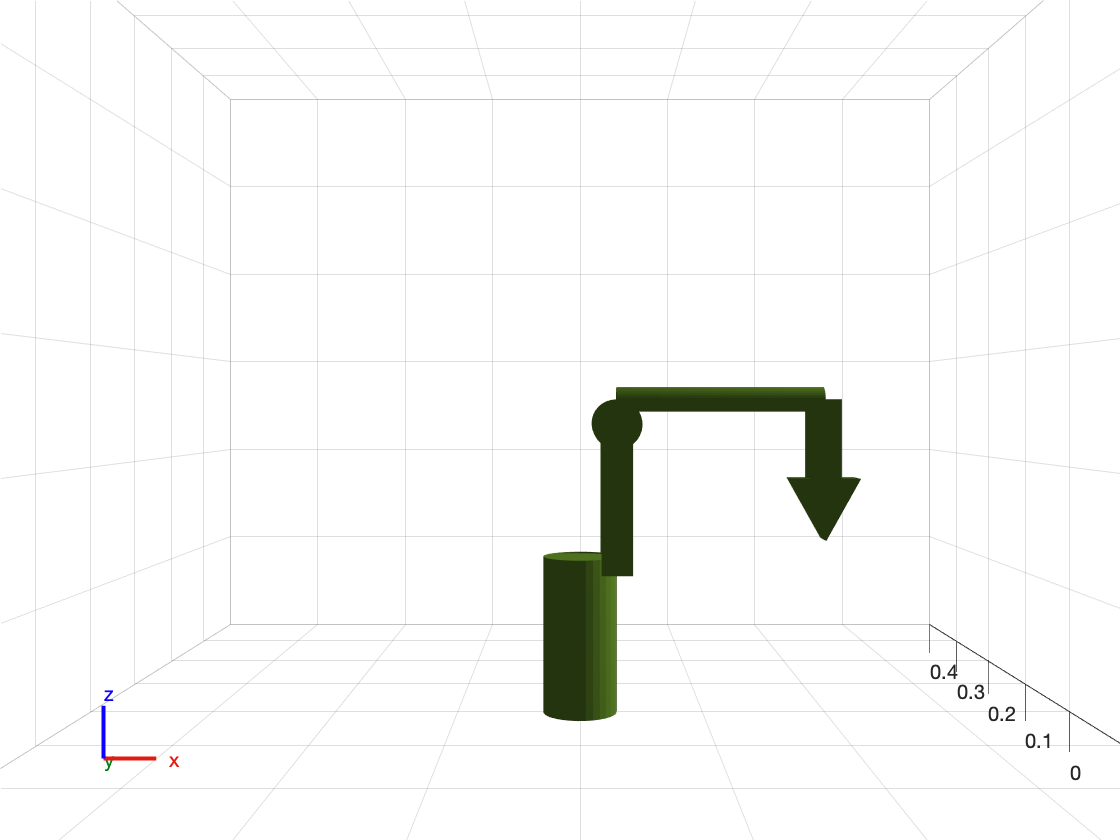

saveFigureAsPDF(gcf, "task-1-frames.png");
 
% Visualize the robot with collision volumes
figure(2);
show(robot, 'Collisions', 'on','Frames','off'); % Show collision volumes
title('Robot with Collision Volumes');
xlim([-0.4 0.4]);
ylim([-0.4 0.4]);
zlim([0 0.6]);
saveFigureAsPDF(gcf, "task-1-collision-box.png");

campos([0, -1, 0.25]); % Camera at (0, -1, 0)
camtarget([0, 0, 0.25]); % Looking towards (0, 0, 0)
camup([0, 0, 1]); % Set the up vector along the Z-axis
camzoom(0.25);

## Use the robot frames for joint space control

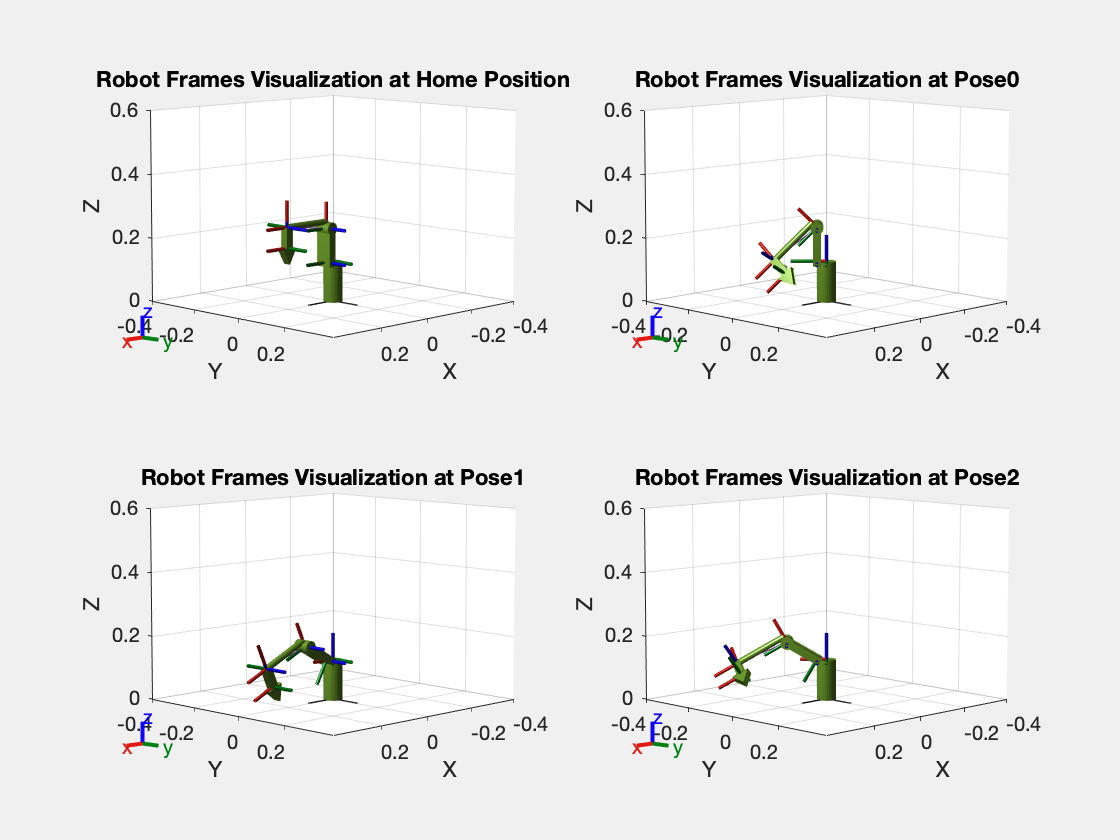

%Define Poses
Q1 = [-pi/4; 0; pi/4; pi/5; 0; 0];
Q2 = [0; pi/3; -pi/5; 0; 0; 0];
Q3 = [-pi/4; pi/3; -pi/6; pi/3; 0; 0];

% Obtain the home configuration of robot
robot_homeconfig = robot.homeConfiguration;

% Adding target configuration to the home configuration
Pose0_config = robot_homeconfig + Q1;
Pose1_config = robot_homeconfig + Q2;
Pose2_config = robot_homeconfig + Q3;

% Visualization with target positions applied
figure(2);
subplot(2,2,1);
show(robot, robot_homeconfig, 'Collisions', 'on','Frames','on');
title('Robot Frames Visualization at Home Position');
xlim([-0.4 0.4]);
ylim([-0.4 0.4]);
zlim([0 0.6]);

subplot(2,2,2);
show(robot, Pose0_config, 'Collisions', 'on','Frames','on');
title('Robot Frames Visualization at Pose0');
xlim([-0.4 0.4]);
ylim([-0.4 0.4]);
zlim([0 0.6]);

subplot(2,2,3);
show(robot, Pose1_config, 'Collisions', 'on','Frames','on');
title('Robot Frames Visualization at Pose1');
xlim([-0.4 0.4]);
ylim([-0.4 0.4]);
zlim([0 0.6]);

subplot(2,2,4);
show(robot, Pose2_config, 'Collisions', 'on','Frames','on');
title('Robot Frames Visualization at Pose2');
xlim([-0.4 0.4]);
ylim([-0.4 0.4]);
zlim([0 0.6]);
saveFigureAsPDF(gcf, "task-1-poses.png");

Animate

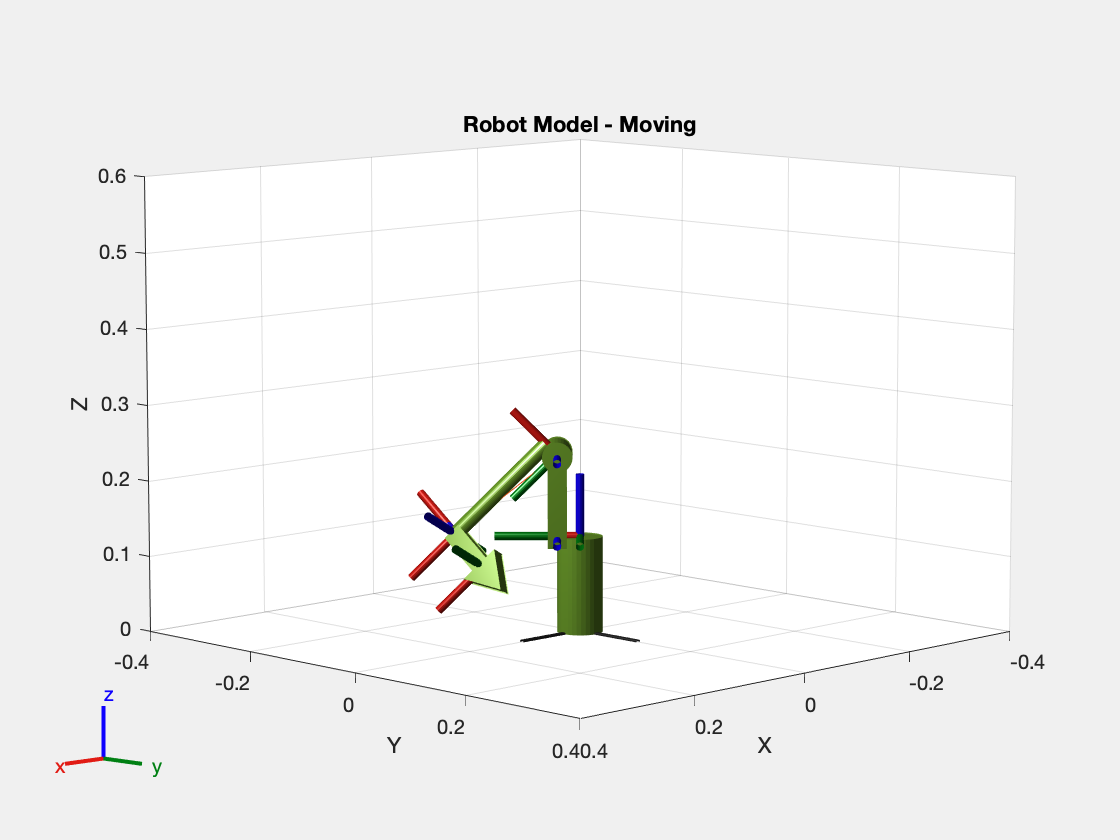


% Step 4: Interpolate between initial and target configurations
numSteps = 10;  % Increase steps to slow down the animation
trajectory1 = zeros(numSteps, 6);
trajectory2 = zeros(numSteps, 6);
trajectory3 = zeros(numSteps, 6);
for j = 1:6
    trajectory1(:, j) = linspace(Pose0_config(j), Pose1_config(j), numSteps);
    trajectory2(:, j) = linspace(Pose1_config(j), Pose2_config(j), numSteps);
    trajectory3(:, j) = linspace(Pose2_config(j), Pose0_config(j), numSteps);
end

% Step 5: Animate the robot movement with looped playback

figure;
axes = show(robot, Pose0_config, 'Frames', 'on', 'Collisions', 'on');
title('Robot Model - Moving');
xlim([-0.4 0.4]);
ylim([-0.4 0.4]);
zlim([0 0.6]);
hold on;

for j = 1:3
    for i = 1:numSteps

        if j == 1
            config = trajectory1(i, :);
            show(robot, config', 'Frames', 'on', 'PreservePlot', false, 'Collisions', 'on');
            drawnow;
        end
        if j == 2
            config = trajectory2(i, :);
            show(robot, config', 'Frames', 'on', 'PreservePlot', false, 'Collisions', 'on');
            drawnow;
        end
        if j == 3
            config = trajectory3(i, :);
            show(robot, config', 'Frames', 'on', 'PreservePlot', false, 'Collisions', 'on');
            drawnow;
        end
    
    end
end

hold off;

## Forward kinematics

syms th1 th2 th3 th4 th5 th6;   % Do not forget to install 'Symbolic Math Toolbox'
joint_angles_sym = [th1 th2 th3 th4 th5 th6];
num_joints = length(joint_angles_sym);

T_cumul = zeros(4, 4);
T_cur = zeros(4, 4);

for i = 1:6
    a = dhparams(i, 1);
    alpha = dhparams(i, 2);
    d = dhparams(i, 3);
    theta = home_joint_angles(i) + joint_angles_sym(i);
    T_cur = transformation_matrix(a, alpha, d, theta);
    if i == 1
        T_cumul = T_cur;
    else
        T_cumul = T_cumul * T_cur;
    end
end

transformation_matrix_ee_sym = simplify(T_cumul);

% just testing

all_zeros = zeros(1, 6);

tip_pos = fk(transformation_matrix_ee_sym, joint_angles_sym, all_zeros);
disp(tip_pos);

  198.6700
    0.0000
  190.7100



## Coppelia Sim

% Check before requiring the 'sim' module
host = '127.0.0.1'; % CoppeliaSim IP
port = 23000;       % Port CoppeliaSim ZeroMQ is listening on
isSimLoaded = false; 
% Try connecting to the specified host and port

try
    tcpClient = tcpclient(host, port, 'Timeout', 5); % 5-second timeout
    fprintf('Connection to CoppeliaSim is successful.\n');
    clear tcpClient;
    isSimLoaded = true; 
catch
    error('Could not connect to CoppeliaSim. Ensure it is running and the port is open.');
end

Connection to CoppeliaSim is successful.



fprintf('Program started\n')

Program started



% Initialize RemoteAPIClient and connect to CoppeliaSim
client = RemoteAPIClient();
sim = client.require('sim');

% Match the robot's joint names (modify as needed based on your robot model object alias in simulation)
Name_joints = {'/Mirobot/joint1', '/Mirobot/joint2', '/Mirobot/joint3', '/Mirobot/joint4', '/Mirobot/joint5', '/Mirobot/joint6'};
Name_Tip = '/Mirobot/Tip';
Num_joints = length(Name_joints);
% Retrieve handles for each joint
Handles_joints = zeros(Num_joints, 1);

for i = 1 : Num_joints
    Handles_joints(i) = sim.getObject(Name_joints{i});
end
Handles_tip = sim.getObject(Name_Tip);

% validate between coppelia and forward kinematics model

sim.startSimulation();

dt = 1;
executing_time = 3;
starting_pos = [0 0 0 0 0 0];
ending_pos = ones(1, 6) .* pi/8;
t_step = 0:dt:executing_time;
step_pos = interp1([0, executing_time],[starting_pos; ending_pos],t_step);
tip_positions = zeros(length(t_step),3);

for i = 1:Num_joints
    sim.setJointPosition(Handles_joints(i), starting_pos(i));
end

disp('Jogging the robot by directly setting joint position');

Jogging the robot by directly setting joint position


for steps = 1:length(t_step)
    for i = 1:Num_joints
        sim.setJointTargetPosition(Handles_joints(i), step_pos(steps,i));
    end
    Tip_pose_array = sim.getObjectPosition(Handles_tip);
    tip_positions(steps, 1:3) = [Tip_pose_array{1:3}];
    sim.wait(dt);
end

disp('End jogging');

End jogging


pause(2);
sim.stopSimulation();
fprintf('Program ended\n');

Program ended


tip_positions = tip_positions(2:end, :); 

start_pos_actual = tip_positions(1, :)' .* 1000;
start_pos_predicted = fk(transformation_matrix_ee_sym, joint_angles_sym, starting_pos);

disp("start position");

start position


fprintf("%.0f ", rad2deg(starting_pos));

0 0 0 0 0 0 

disp("actual");

actual


fprintf("%.0f ", start_pos_actual');

198 2 189 

disp("predicted");

predicted


fprintf("%.0f ", start_pos_predicted');

199 0 191 

end_pos_actual = tip_positions(end, :)' .* 1000;
end_pos_predicted = fk(transformation_matrix_ee_sym, joint_angles_sym, ending_pos);

disp("end position");

end position


fprintf("%.1f ", rad2deg(ending_pos));

22.5 22.5 22.5 22.5 22.5 22.5 

disp("end position");

end position


disp("actual");

actual


fprintf("%.0f ", end_pos_actual');

159 62 118 

disp("predicted");

predicted


fprintf("%.0f ", end_pos_predicted');

128 78 100 

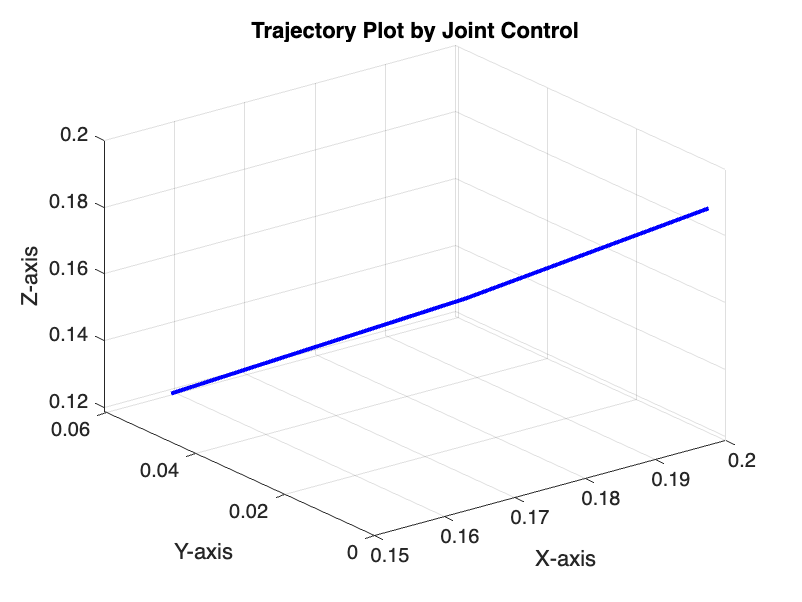

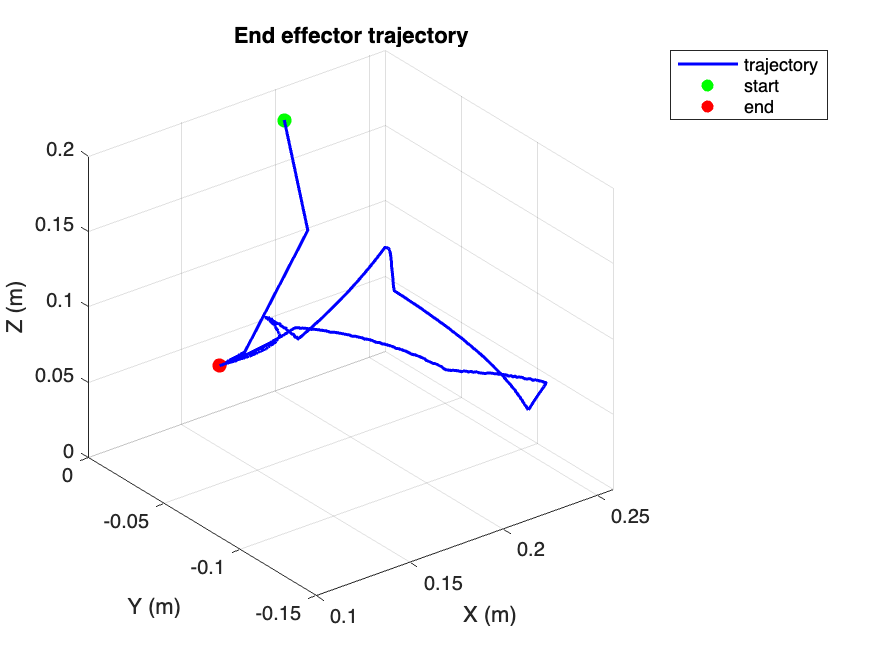

started

% not really required, just copied from tutorial

% Extract X, Y, and Z coordinates from the trajectory array
X = tip_positions(:, 1);
Y = tip_positions(:, 2);
Z = tip_positions(:, 3);
% Arrange the plotting space
xlim([-0.35, 0.35]); 
ylim([-0.35, 0.35]); 
zlim([-0.8, 0.45]);
% Plot the trajectory as a 3D line
plot3(X, Y, Z, 'b', 'LineWidth', 2);
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Trajectory Plot by Joint Control');
grid on;

## Task 2

q0 = [-pi/4, 0, pi/4, pi/5, 0, 0];
q1 = [0, pi/3, -pi/5, 0, 0, 0];
q2 = [-pi/4, pi/3, -pi/6, pi/3, 0, 0];

joint_angles = [
    q0;
    q1;
    q2;
    q0;
];

foo = refine(joint_angles, 200);

joint_angles_interpolated = foo;
joint_angles = joint_angles_interpolated;

if false
    save('task_2_joint_angles.mat', 'joint_angles');
    clear joint_angles;
else
    loaded_data = load('task_2_joint_angles.mat');
    joint_angles = loaded_data.joint_angles;
end

sim.startSimulation();
ys = joint_angles;

dt = 0.050;
tip_positions = zeros(size(ys, 1),3);
tip_linear_speeds = zeros(1, size(ys, 1));
tip_angular_speeds = zeros(1, size(ys, 1));

joint_positions = zeros(size(ys, 1), Num_joints, 3);
joint_linear_speeds = zeros(size(ys, 1), Num_joints);
joint_angular_speeds = zeros(size(ys, 1), Num_joints);

for i = 1:Num_joints
    sim.setJointPosition(Handles_joints(i), ys(1, i));
end

disp('Jogging the robot by directly setting joint position');

Jogging the robot by directly setting joint position


for i = 1:size(ys, 1)
    for j = 1:Num_joints
        sim.setJointTargetPosition(Handles_joints(j), ys(i,j));
    end
    for j = 1:Num_joints
        joint_pose_array = sim.getObjectPosition(Handles_joints(j));
        joint_positions(i, j, 1:3) = [joint_pose_array{1:3}];
        [linear_velocity, angular_velocity] = sim.getObjectVelocity(Handles_joints(j));
        joint_linear_speeds(i, j) = sqrt(sum([linear_velocity{1:3}].^2, 2));
        joint_angular_speeds(i, j) = sqrt(sum([[angular_velocity{1:3}]].^2, 2));
    end
    Tip_pose_array = sim.getObjectPosition(Handles_tip);
    tip_positions(i, 1:3) = [Tip_pose_array{1:3}];
    [linear_velocity, angular_velocity] = sim.getObjectVelocity(Handles_tip);
    tip_linear_speeds(i) = sqrt(sum([linear_velocity{1:3}].^2, 2));
    tip_angular_speeds(i) = sqrt(sum([[angular_velocity{1:3}]].^2, 2));
    sim.wait(dt);
end

Error using RemoteAPIClient/call (line 130)
347: in sim.getObjectVelocity: argument 1 is not a number.

Error in indexing (


disp('End jogging');
pause(2);
sim.stopSimulation();
fprintf('Program ended\n');

tip_positions = tip_positions(2:end, :);
tip_linear_speeds = tip_linear_speeds(:, 2:end);
tip_angular_speeds = tip_angular_speeds(:, 2:end);

joint_positions = joint_positions(2:end, :, :);
joint_linear_speeds = joint_linear_speeds(2:end, :);
joint_angular_speeds = joint_angular_speeds(2:end, :);

tip_positions = tip_positions .* 1000;
tip_linear_speeds = tip_linear_speeds .* 1000;
tip_angular_speeds = rad2deg(tip_angular_speeds);

joint_positions = joint_positions .* 1000;
joint_linear_speeds = joint_linear_speeds .* 1000;
joint_angular_speeds = rad2deg(joint_angular_speeds);

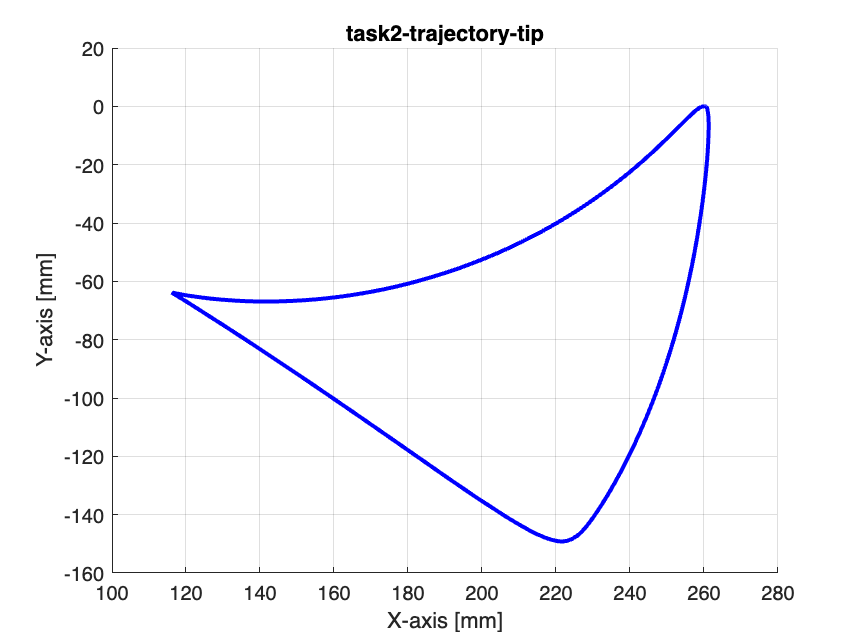

foo = "task2-trajectory-";
plot_obj_trajectory_task_2(tip_positions, foo + "tip");

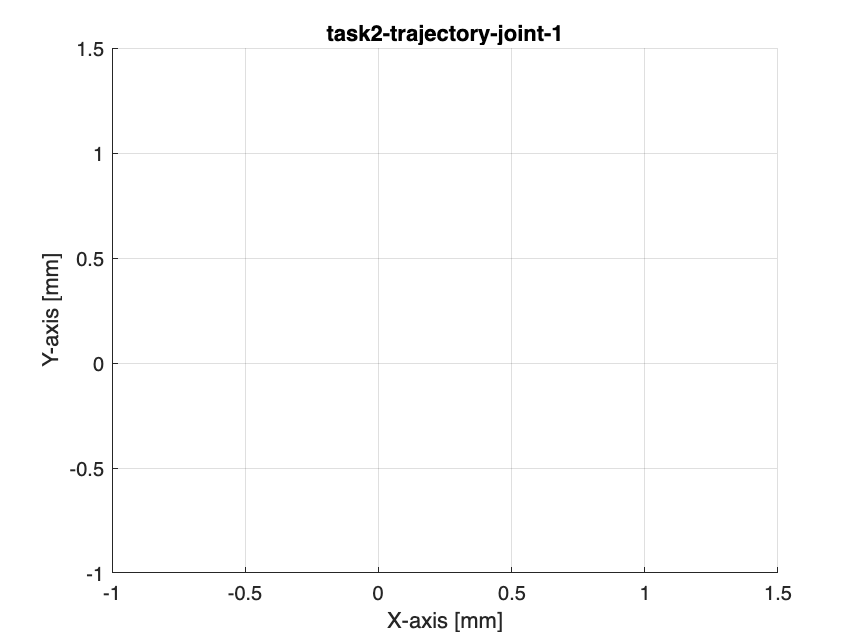

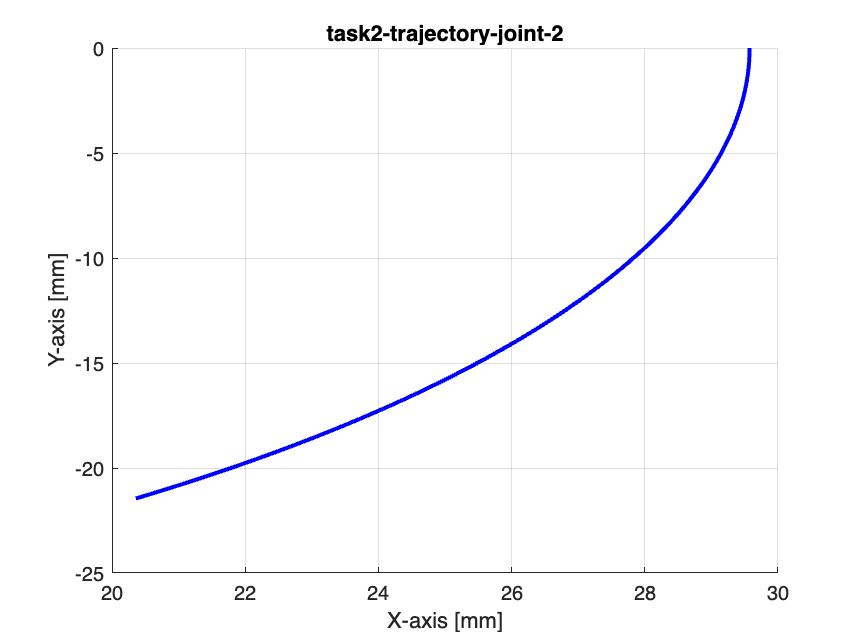

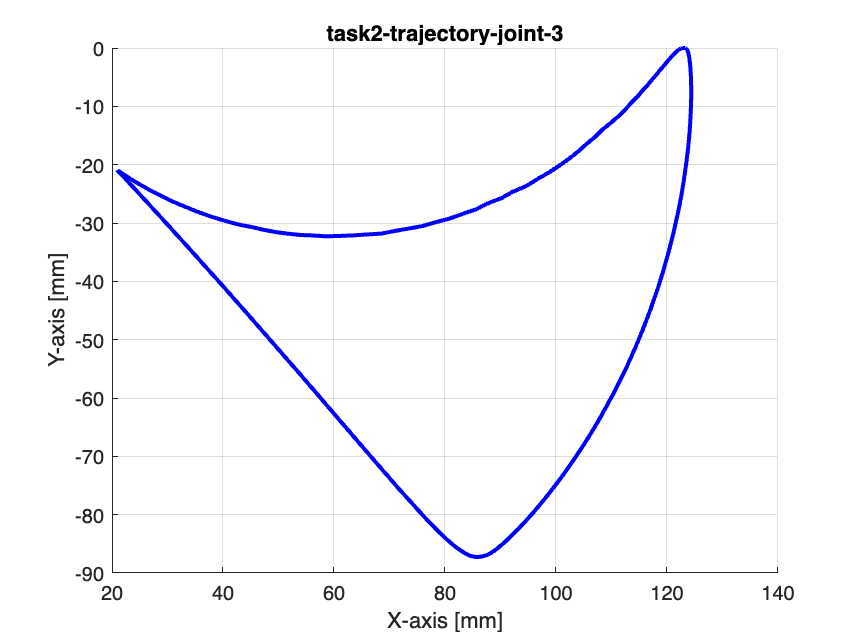

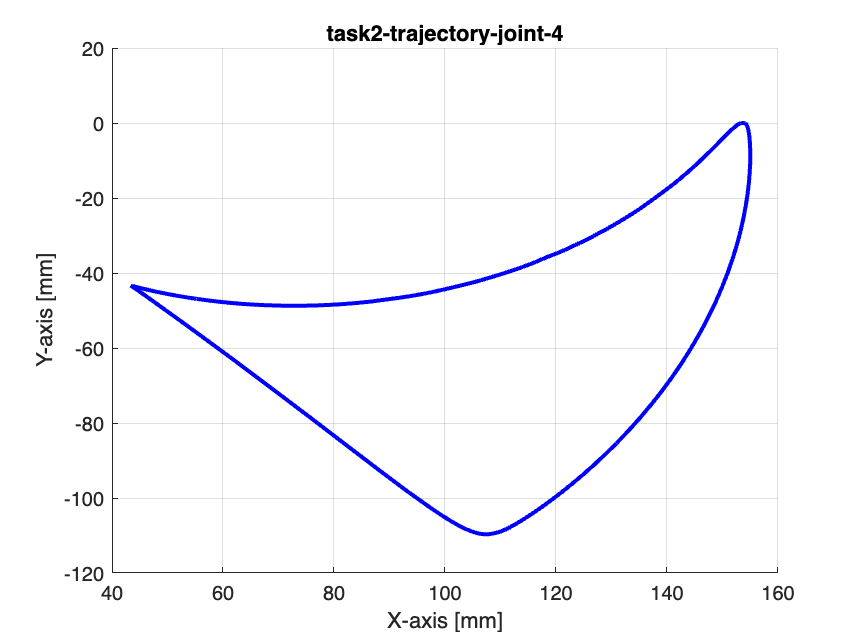

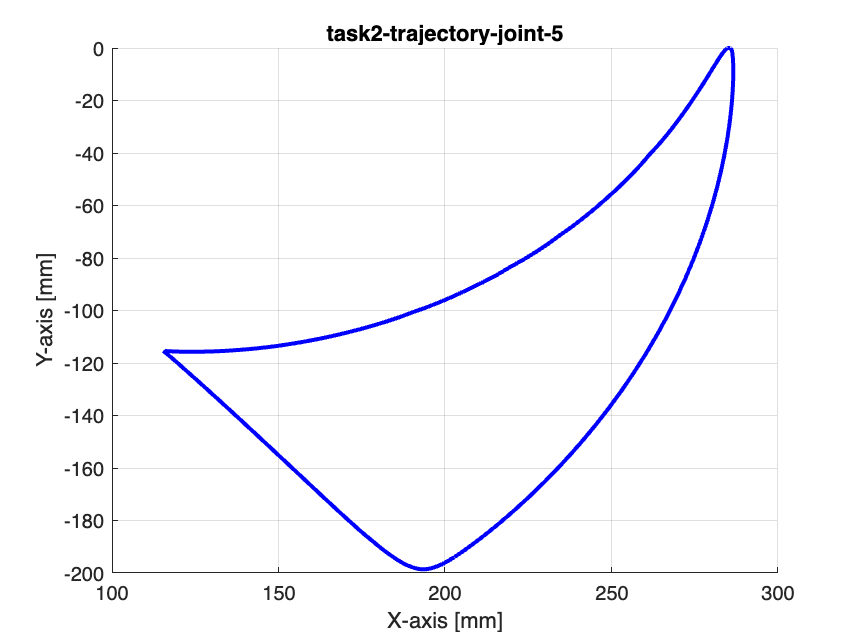

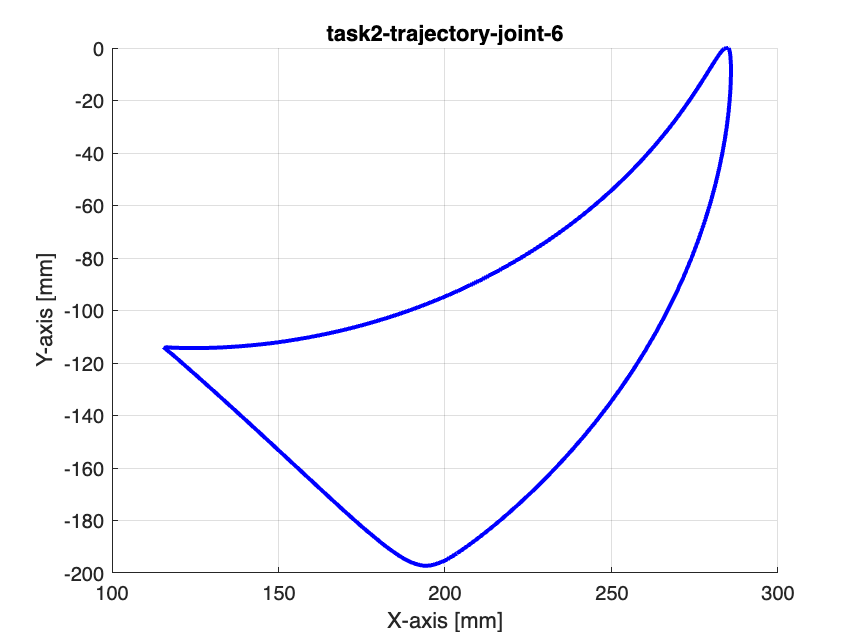

for i = 1:Num_joints
    plot_obj_trajectory_task_2(joint_positions(:, i, :), foo + sprintf("joint-%d", i));
end

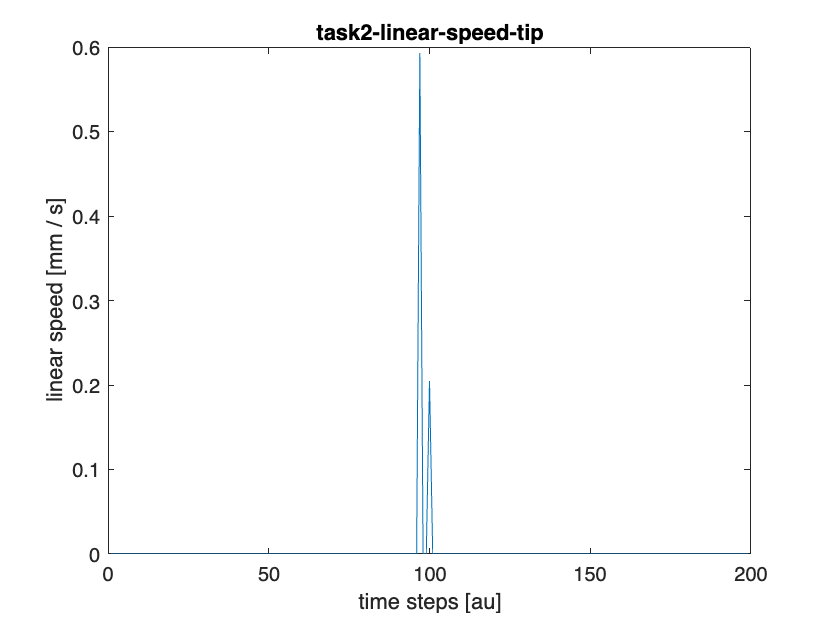

foo = "task2-linear-speed-";
plot_obj_linear_speed(tip_linear_speeds, foo + "tip");

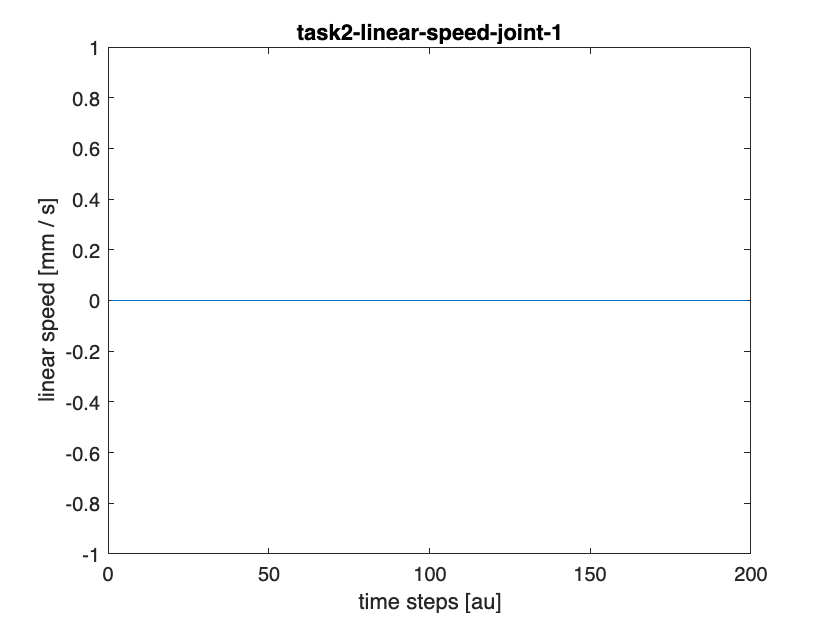

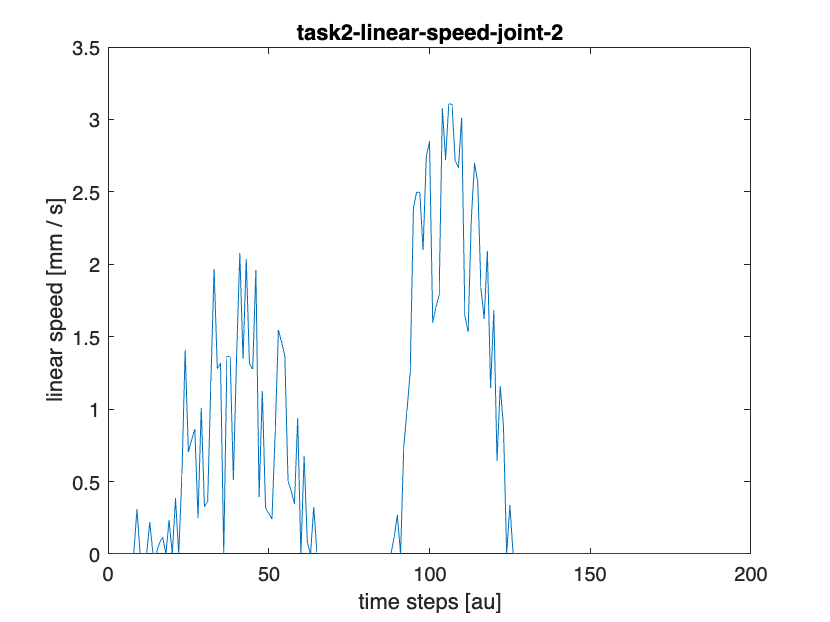

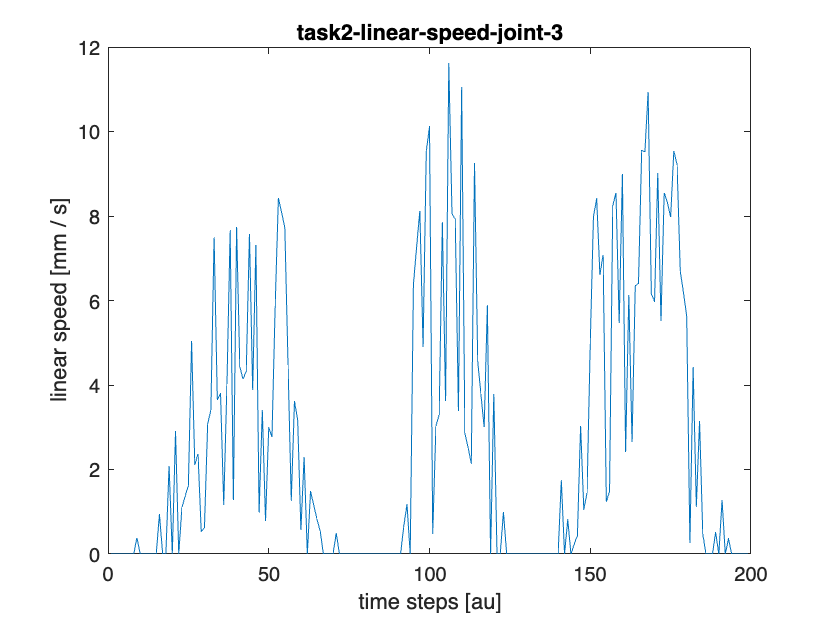

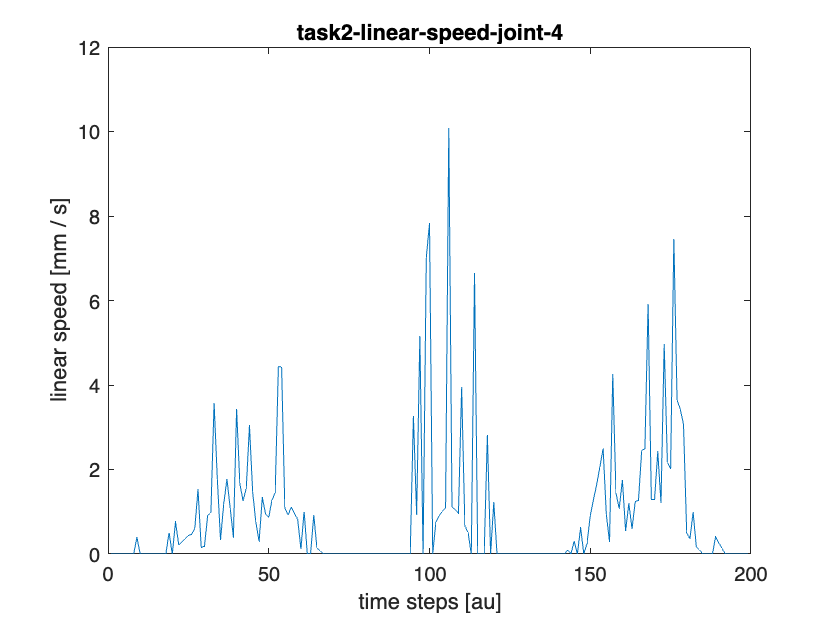

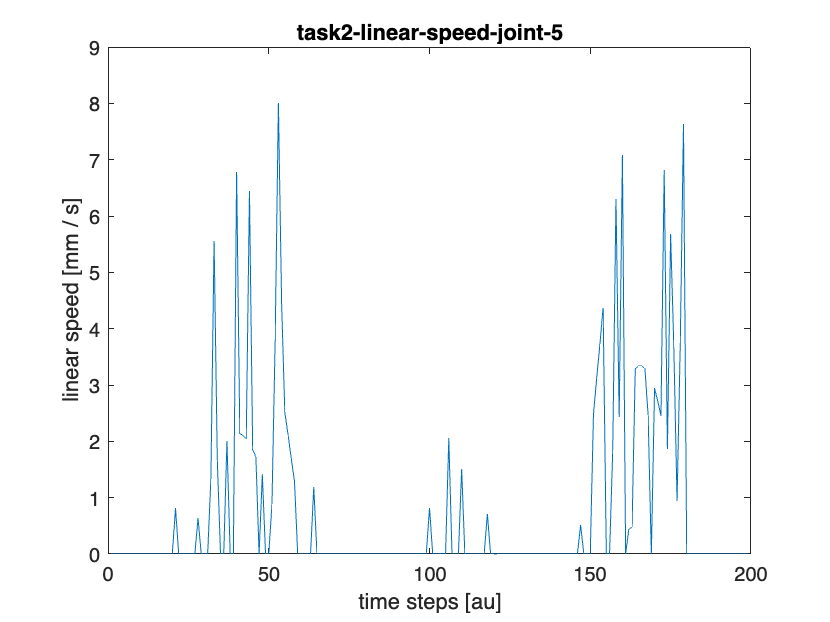

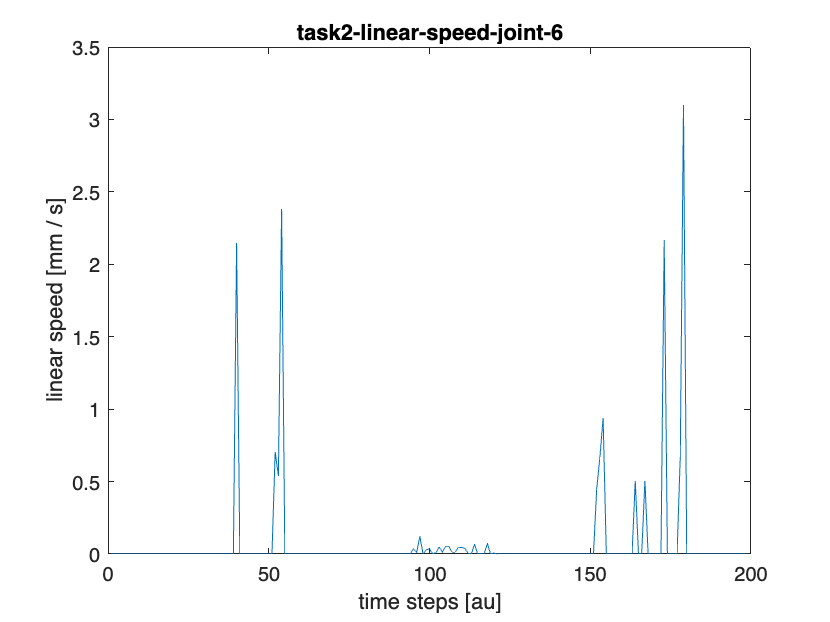

for i = 1:Num_joints
    plot_obj_linear_speed(squeeze(joint_linear_speeds(:, i)), foo + sprintf("joint-%d", i));
end 

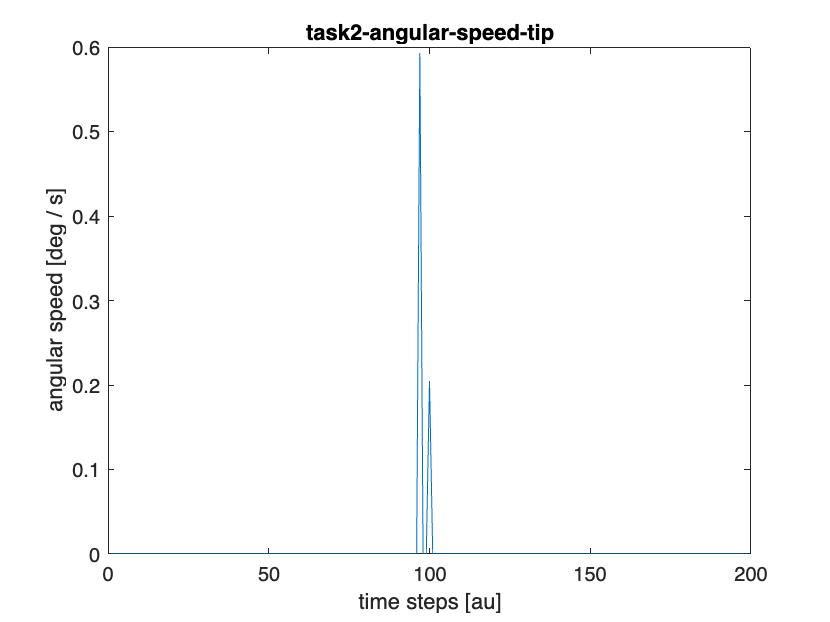


foo = "task2-angular-speed-";
plot_obj_angular_speed(tip_linear_speeds, foo + "tip");

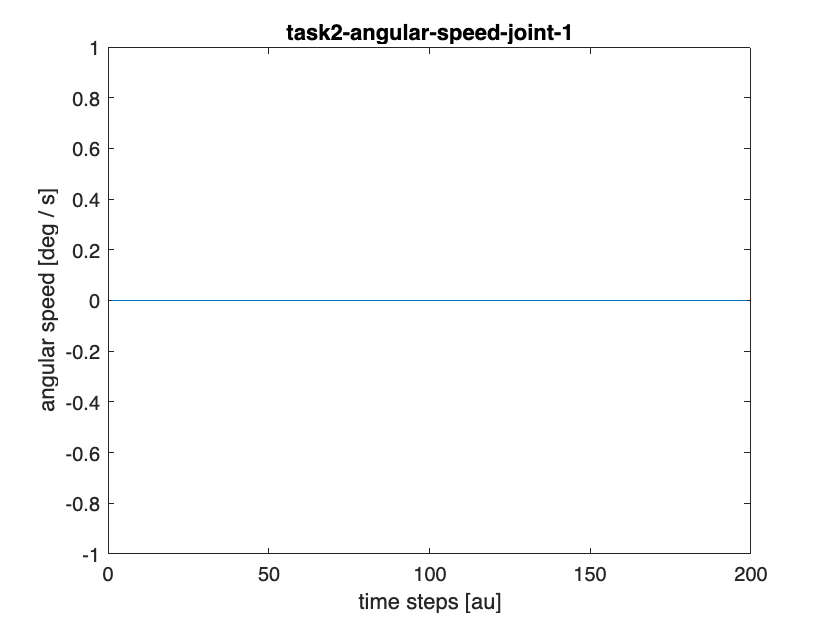

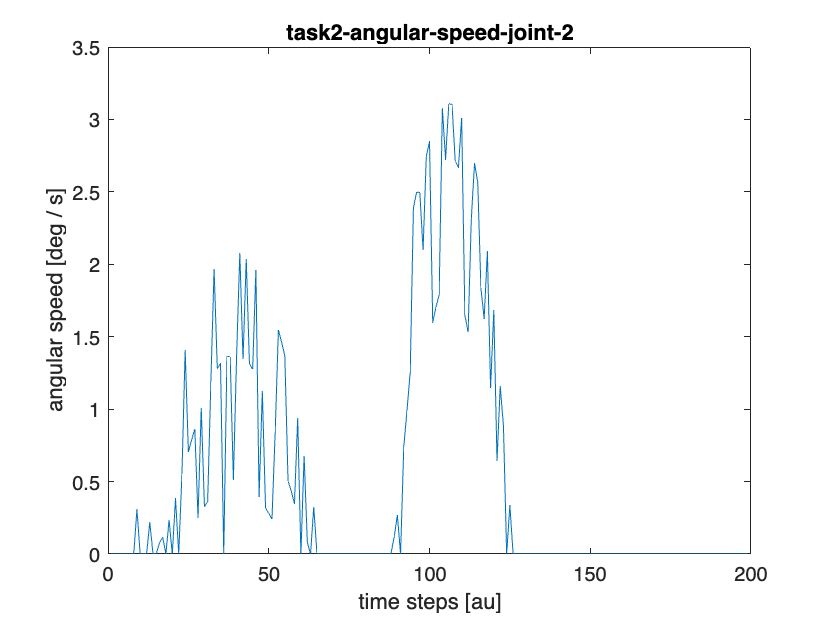

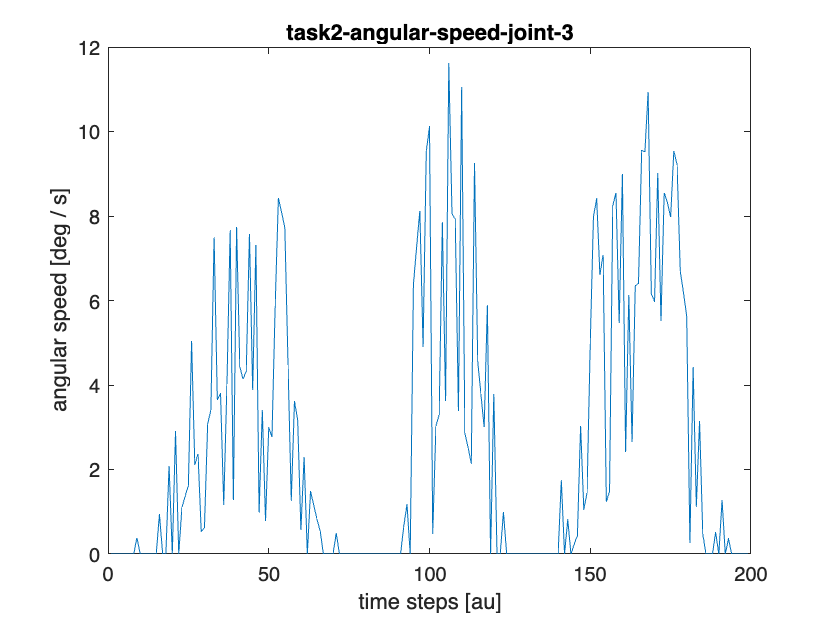

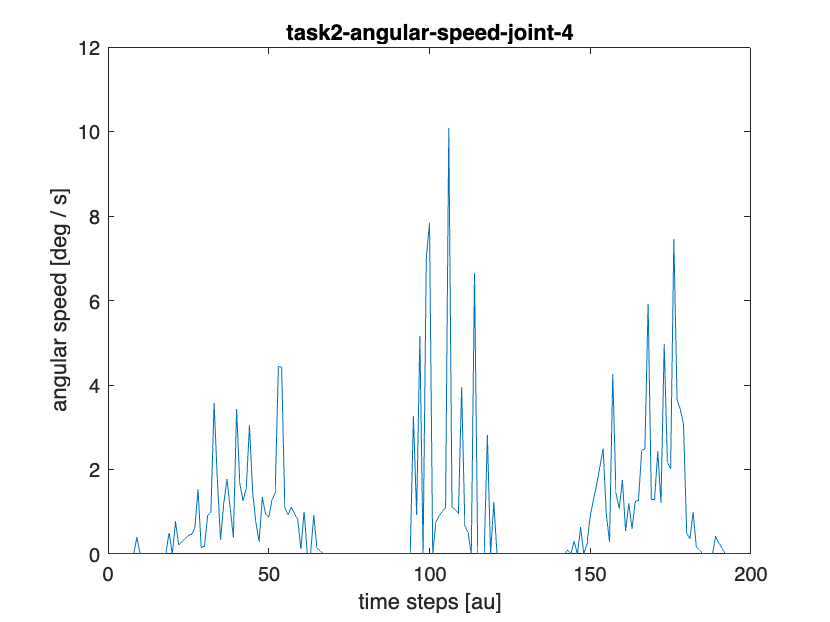

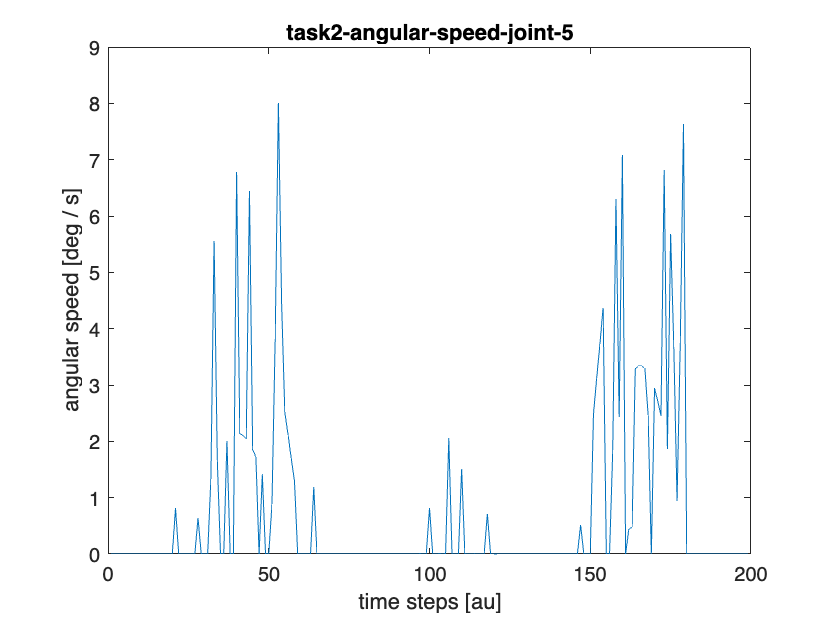

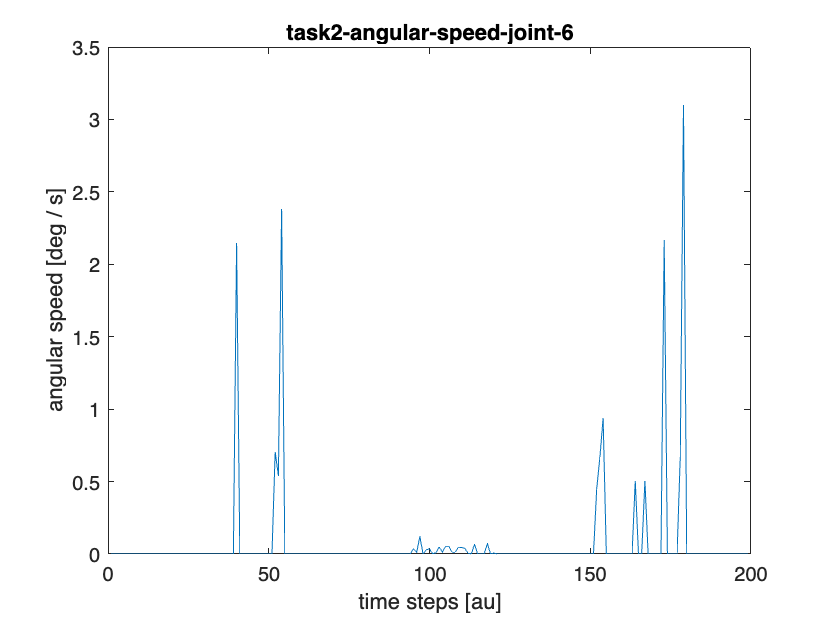

for i = 1:Num_joints
    plot_obj_angular_speed(squeeze(joint_linear_speeds(:, i)), foo + sprintf("joint-%d", i));
end 

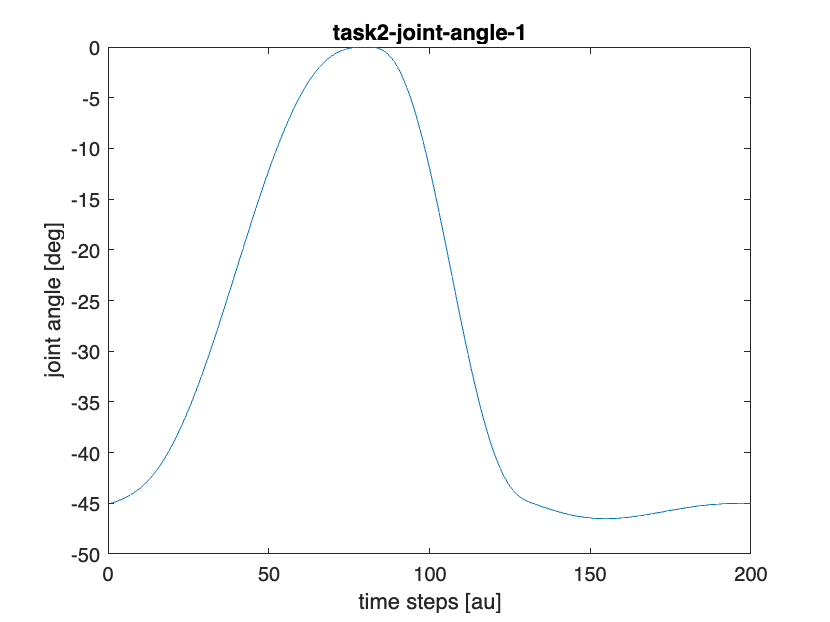

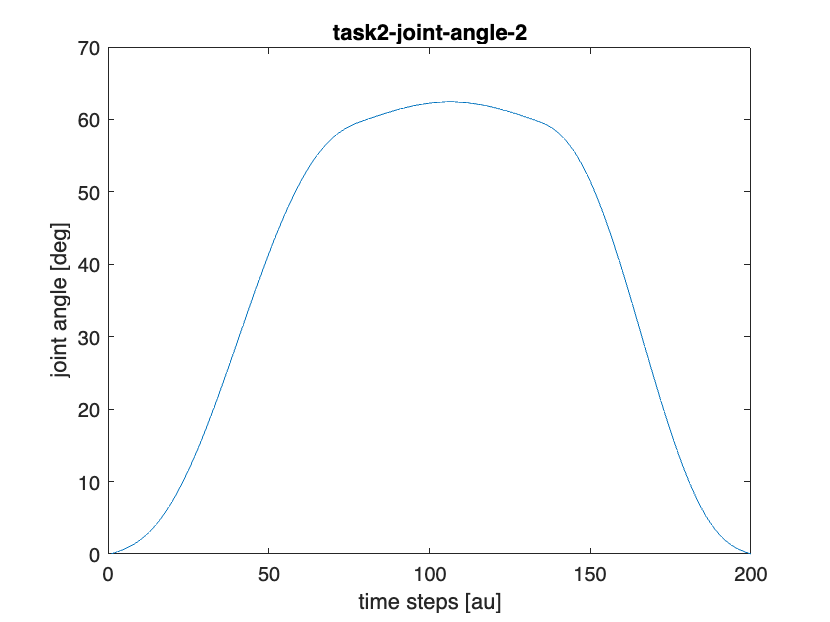

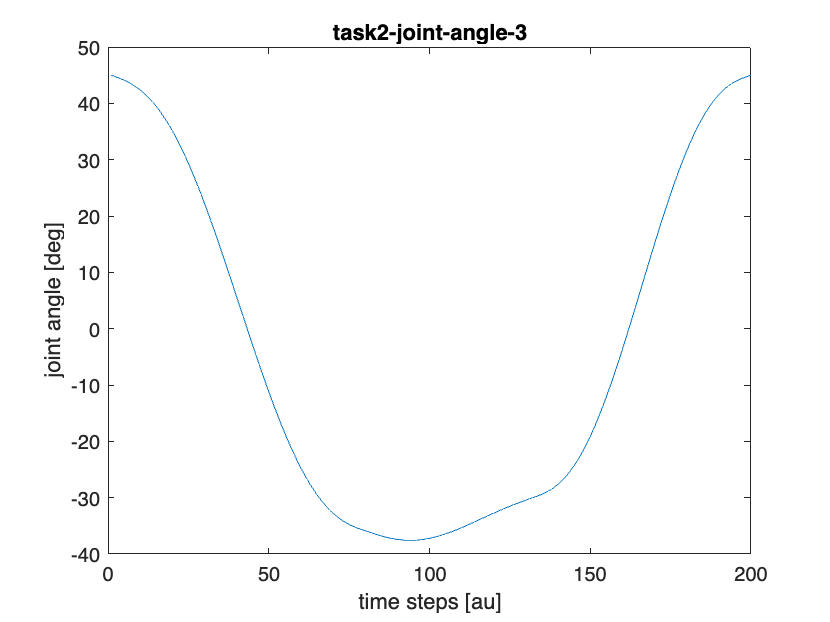

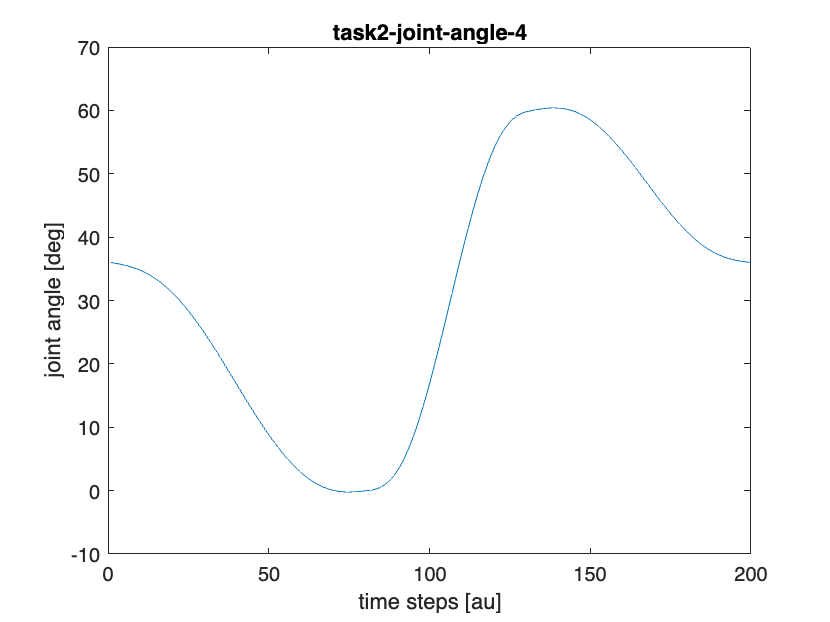

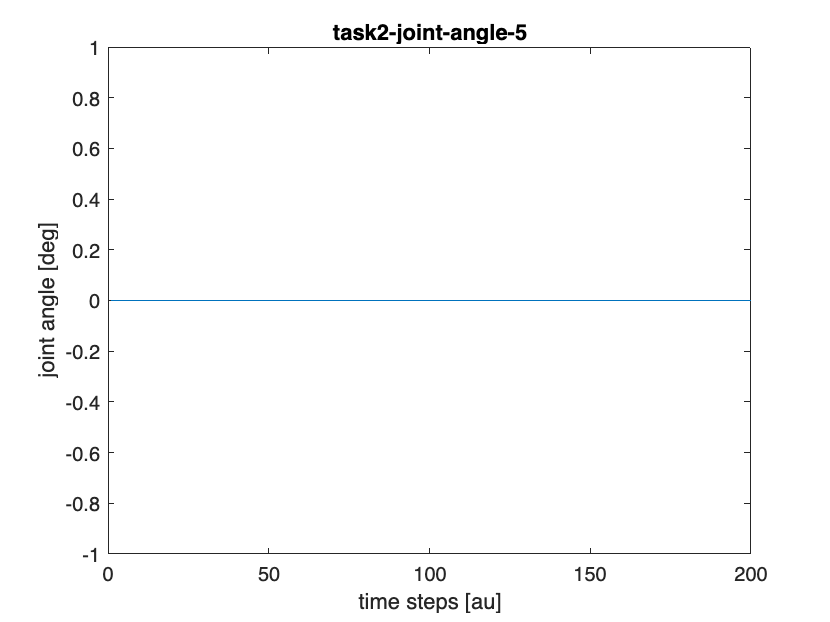

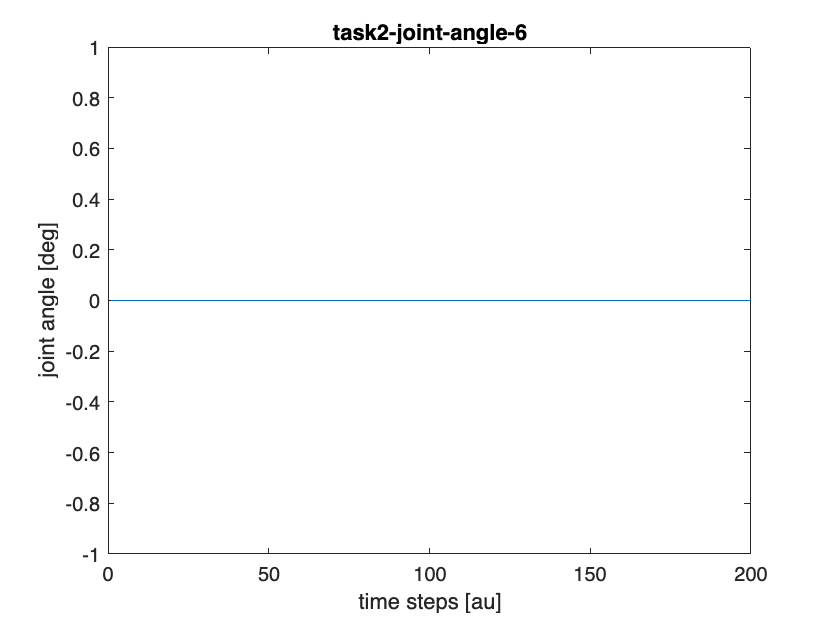


foo = "task2-joint-angle-";
for i = 1:Num_joints
    ys_deg = rad2deg(ys(:, i));
    fig_handle = figure;
    plot(ys_deg, "-");
    xlabel("time steps [au]");
    ylabel("joint angle [deg]");
    title(foo + i);
    filename = foo + sprintf("%d", i) + file_format;
    saveFigureAsPDF(fig_handle, filename);
    % saveas(gcf, filename);
end

mirobot = Mirobot_Matlab; 
s = mirobot.Mirobotconnect('/dev/tty.usbserial-14430'); %connect to /dev/tty.usbserial-10 for example
disp('Finish');

Finish


pause(2);

disp('Testing zeroing');

Testing zeroing


mirobot.go_to_zero(s); %return back to initial position
pause(2);

mirobot_xs = joint_angles_interpolated;

disp('Testing joint control');

Testing joint control


for i = 1:size(mirobot_xs, 1)
    angle_radians = squeeze(mirobot_xs(i, :));
    a = rad2deg(angle_radians);
    formatted_angles = cell(1, 6);
    
    % Loop through each element and store the formatted values
    for j = 1:6
        formatted_angles{j} = sprintf('%.2f', a(j));  % Format each angle
    end
    
    % If you want to access individual formatted values, you can use
    a1 = formatted_angles{1};
    a2 = formatted_angles{2};
    a3 = formatted_angles{3};
    a4 = formatted_angles{4};
    a5 = formatted_angles{5};
    a6 = formatted_angles{6};
    msg = mirobot.go_to_axis(s, a1, a2, a3, a4, a5, a6);
    if i == 1
        % 3 s
        pause(3);
    else
        % 50 ms
        pause(0.050);
    end
end

## Task 3

% hard-coded joint angles for task 3 initial position - obtained from
% WLKata studio; used for initial guess of Newton Raphson method to make
% convergence easier

task_3_joint_angles_initial_position = [0.0, -21.463, -8.828, 0.0, -59.715, 0.0];
% random_offsets = -15 + (15 - (-15)) * rand(1, 6);
% task_3_joint_angles_initial_position = task_3_joint_angles_initial_position + random_offsets;
task_3_joint_angles_initial_position = deg2rad(task_3_joint_angles_initial_position);
task_3_joint_angles_initial_position = task_3_joint_angles_initial_position;
task_3_initial_position_cartesian = fk(transformation_matrix_ee_sym, joint_angles_sym, task_3_joint_angles_initial_position);
task_3_initial_position_cartesian

task_3_initial_position_cartesian =   190.2849
   -0.0000
  330.0190



task_2_joint_angles_initial_position = [0.0, 54.47, 46.188, 0.0, -190.655, 0.0];
% random_offsets = -15 + (15 - (-15)) * rand(1, 6);
% task_2_joint_angles_initial_position = task_2_joint_angles_initial_position + random_offsets;
task_2_joint_angles_initial_position = deg2rad(task_2_joint_angles_initial_position);
task_2_joint_angles_initial_position = task_2_joint_angles_initial_position;
task_2_initial_position_cartesian = fk(transformation_matrix_ee_sym, joint_angles_sym, task_2_joint_angles_initial_position);
task_2_initial_position_cartesian

task_2_initial_position_cartesian =   170.2744
    0.0000
   19.9948



interpolation_factor = 0.003;

R =    -0.0001    0.0000   -1.0000
   -0.0000    1.0000    0.0000
    1.0000    0.0000   -0.0001


q_eul =     0.7071         0   -0.7071         0


eulerAngles =    -3.1416   -1.5707    3.1416


error = 3.8360e-16

ans =     0.7071         0   -0.7071   -0.0000


home_tip_pos_numeric = calc_pose(joint_angles_sym, zeros(1, 6), transformation_matrix_ee_sym);

xyz_spec_waypoints = [
    150 0 330;
    130 0 20;
    285 0 95;
    150 0 330;
];
xyz_spec_waypoints = xyz_spec_waypoints ./ 1000;
xyz_spec_waypoints = xyz_spec_waypoints + [l6 0 0];

waypoints = zeros(7, size(xyz_spec_waypoints, 1));
for i = 1:size(xyz_spec_waypoints, 1)
    [x, y, z] = deal(xyz_spec_waypoints(i, 1), xyz_spec_waypoints(i, 2), xyz_spec_waypoints(i, 3));
    xyz = [x y z];
    quaternion = eul2quat([0 -pi/2 0]);
    waypoints(:, i) = cat(2, xyz, quaternion);
end
waypoints = interpolate_vectors(waypoints, interpolation_factor);
% waypoints: num_waypoints x num_joints
waypoints = waypoints';
num_waypoints = size(waypoints, 1);

if false
    joint_angles = zeros(num_waypoints+1, num_joints);
    joint_angles(1, :) = task_3_joint_angles_initial_position;
    disp(num_waypoints);
    for i = 1:num_waypoints
        waypoint = waypoints(i, :);
        previous_joint_angle_vector = joint_angles(i, :);
        joint_angles_res = calculate_angle_monolithic(joint_angles_sym, transformation_matrix_ee_sym, previous_joint_angle_vector, waypoint);
        joint_angles_res(1, 6) = 0.0;
        joint_angles(i+1, :) = joint_angles_res;
        disp(i);
    end
    joint_angles = joint_angles(2:end, :);
    save('task_3_joint_angles.mat', 'joint_angles');
    clear joint_angles;
end

loaded_data = load('task_3_joint_angles.mat');
joint_angles = loaded_data.joint_angles;
disp(joint_angles);

    0.0000   -0.1828   -0.3045    0.0000   -1.0835         0
    0.0000   -0.2013   -0.2676    0.0000   -1.1019         0
   -0.0000   -0.2190   -0.2318    0.0000   -1.1200         0
   -0.0000   -0.2361   -0.1969    0.0000   -1.1378         0
    0.0000   -0.2526   -0.1629   -0.0000   -1.1553         0
    0.0000   -0.2685   -0.1297    0.0000   -1.1725         0
    0.0000   -0.2839   -0.0974   -0.0000   -1.1895         0
    0.0000   -0.2988   -0.0657    0.0000   -1.2063         0
   -0.0000   -0.3131   -0.0347    0.0000   -1.2229         0
    0.0000   -0.3271   -0.0044    0.0000   -1.2394         0
   -0.0000   -0.3405    0.0254    0.0000   -1.2556         0
   -0.0000   -0.3536    0.0545    0.0000   -1.2718         0
    0.0000   -0.3662    0.0832    0.0000   -1.2878         0
    0.0000   -0.3784    0.1113   -0.0000   -1.3037         0
   -0.0000   -0.3902    0.1389    0.0000   -1.3195         0
   -0.0000   -0.4016    0.1661    0.0000   -1.3352         0
   -0.0000   -0.4127    

disp(rad2deg(joint_angles));

    0.0000  -10.4740  -17.4479    0.0000  -62.0781         0
    0.0000  -11.5310  -15.3329    0.0000  -63.1361         0
   -0.0000  -12.5478  -13.2787    0.0000  -64.1735         0
   -0.0000  -13.5274  -11.2802    0.0000  -65.1924         0
    0.0000  -14.4721   -9.3332   -0.0000  -66.1947         0
    0.0000  -15.3842   -7.4337    0.0000  -67.1821         0
    0.0000  -16.2655   -5.5785   -0.0000  -68.1560         0
    0.0000  -17.1175   -3.7646    0.0000  -69.1179         0
   -0.0000  -17.9417   -1.9895    0.0000  -70.0688         0
    0.0000  -18.7391   -0.2508    0.0000  -71.0100         0
   -0.0000  -19.5110    1.4535    0.0000  -71.9425         0
   -0.0000  -20.2581    3.1252    0.0000  -72.8671         0
    0.0000  -20.9812    4.7660    0.0000  -73.7848         0
    0.0000  -21.6810    6.3774   -0.0000  -74.6964         0
   -0.0000  -22.3580    7.9606    0.0000  -75.6026         0
   -0.0000  -23.0127    9.5169    0.0000  -76.5042         0
   -0.0000  -23.6455   1

% joint_angles_start_from_initial_pos = joint_angles(1+1+interpolation_factor+1:end, :);
joint_angles_start_from_initial_pos = joint_angles;

% validate
task_3_tip_positions_from_fk = zeros(size(joint_angles_start_from_initial_pos, 1), 3);
for i = 1:size(joint_angles_start_from_initial_pos, 1)
    angle_vector = joint_angles_start_from_initial_pos(i, :);
    tip_pos = fk(transformation_matrix_ee_sym, joint_angles_sym, angle_vector);
    tip_pos = tip_pos';
    task_3_tip_positions_from_fk(i, :) = tip_pos;
    if mod(i - 1, interpolation_factor + 1) == 0
        k = (i - 1) / (interpolation_factor + 1) + 1;
        actual = xyz_spec_waypoints(k, :) * 1000;
        fk_res = tip_pos;
        tolerance = 1e0;
        assert(all(abs(actual - fk_res) < tolerance), 'FK cartesian coords don't validate IK results');
    end
end
disp(task_3_tip_positions_from_fk);

% (optional) view a collision-box video

video_positions = fine_positions;
desired_num_frames = 20;
downsampling_factor = fix(double(size(video_positions, 1)) / desired_num_frames);
video_positions_downsampled = video_positions(1:downsampling_factor:end, :);

% (optional) view a collision-box video

video_xs = video_positions_downsampled;
actual_num_frames = size(video_xs, 1);
 
% figure;
hold off;
F(actual_num_frames) = struct('cdata', [], 'colormap', []); % Preallocate frames

% play video
for i = 1 : size(video_xs, 1)
    position = video_xs(i, :);
    position = position';
    assert(isequal(size(position), [6,1]));

    show(robot,position,'Collisions','on','Frames','off');
    campos([0, -1, 0.0]); % Camera at (0, -1, 0)
    camtarget([0, 0, 0.0]); % Looking towards (0, 0, 0)
    camup([0, 0, 1]); % Set the up vector along the Z-axis
    camzoom(0.2);
    F(i) = getframe(gcf);

    drawnow
end

% (optional) view a collision-box video

writerObj = VideoWriter('cw1.avi');
video_time_sec = 5;
writerObj.FrameRate = fix(double(actual_num_frames) / 5);
open(writerObj);
for i=1:length(F)
    frame = F(i) ;    
    writeVideo(writerObj, frame);
end
close(writerObj);

sim.startSimulation();
ys = joint_angles;

dt = 0.050;
tip_positions = zeros(size(ys, 1),3);
tip_linear_speeds = zeros(1, size(ys, 1));
tip_angular_speeds = zeros(1, size(ys, 1));

joint_positions = zeros(size(ys, 1), Num_joints, 3);
joint_linear_speeds = zeros(size(ys, 1), Num_joints);
joint_angular_speeds = zeros(size(ys, 1), Num_joints);

for i = 1:Num_joints
    sim.setJointPosition(Handles_joints(i), ys(1, i));
end

disp('Jogging the robot by directly setting joint position');

Jogging the robot by directly setting joint position


for i = 1:size(ys, 1)
    for j = 1:Num_joints
        sim.setJointTargetPosition(Handles_joints(j), ys(i,j));
    end
    for j = 1:Num_joints
        joint_pose_array = sim.getObjectPosition(Handles_joints(j));
        joint_positions(i, j, 1:3) = [joint_pose_array{1:3}];
        [linear_velocity, angular_velocity] = sim.getObjectVelocity(Handles_joints(j));
        joint_linear_speeds(i, j) = sqrt(sum([linear_velocity{1:3}].^2, 2));
        joint_angular_speeds(i, j) = sqrt(sum([[angular_velocity{1:3}]].^2, 2));
    end
    Tip_pose_array = sim.getObjectPosition(Handles_tip);
    tip_positions(i, 1:3) = [Tip_pose_array{1:3}];
    [linear_velocity, angular_velocity] = sim.getObjectVelocity(Handles_tip);
    tip_linear_speeds(i) = sqrt(sum([linear_velocity{1:3}].^2, 2));
    tip_angular_speeds(i) = sqrt(sum([[angular_velocity{1:3}]].^2, 2));
    sim.wait(dt);
end

disp('End jogging');

End jogging


pause(2);
sim.stopSimulation();
fprintf('Program ended\n');

Program ended



tip_positions = tip_positions(2:end, :);
tip_linear_speeds = tip_linear_speeds(:, 2:end);
tip_angular_speeds = tip_angular_speeds(:, 2:end);

joint_positions = joint_positions(2:end, :, :);
joint_linear_speeds = joint_linear_speeds(2:end, :);
joint_angular_speeds = joint_angular_speeds(2:end, :);

tip_positions = tip_positions .* 1000;
tip_linear_speeds = tip_linear_speeds .* 1000;
tip_angular_speeds = rad2deg(tip_angular_speeds);

joint_positions = joint_positions .* 1000;
joint_linear_speeds = joint_linear_speeds .* 1000;
joint_angular_speeds = rad2deg(joint_angular_speeds);

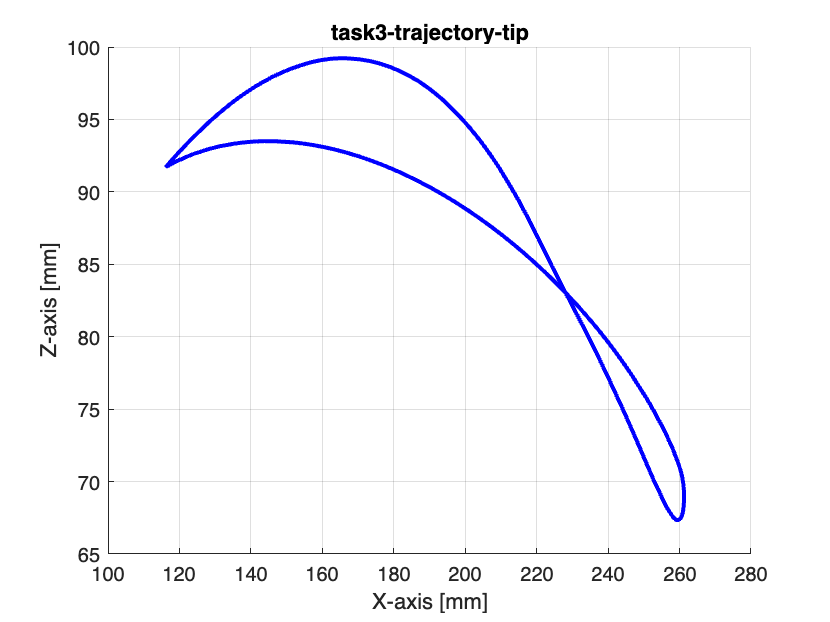

foo = "task3-trajectory-";
plot_obj_trajectory_task_3(tip_positions, false, foo + "tip");

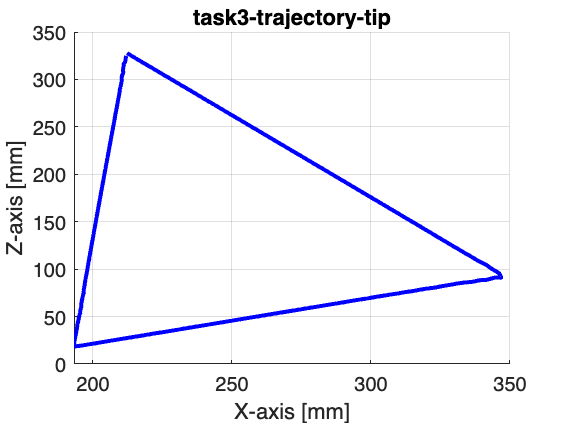

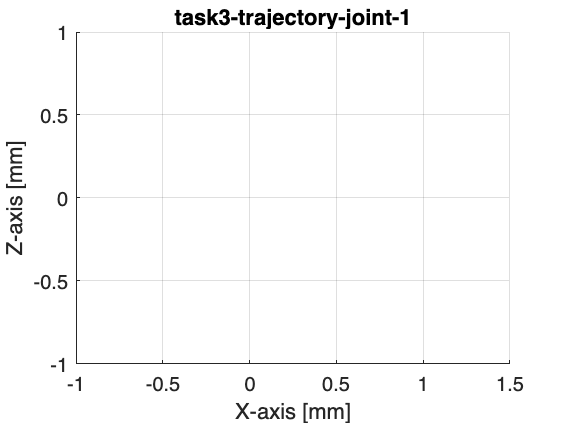

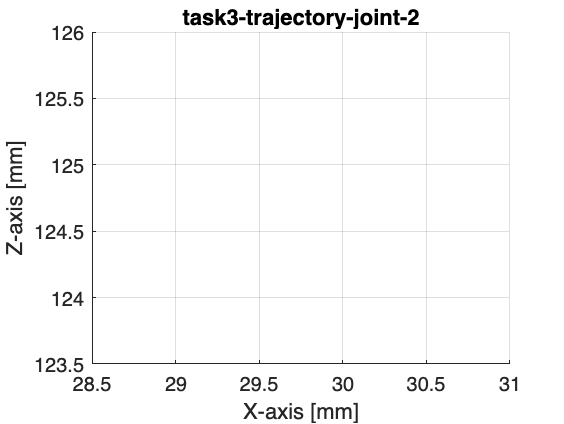

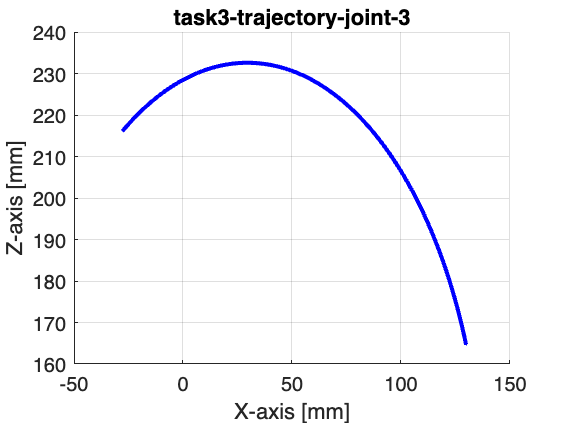

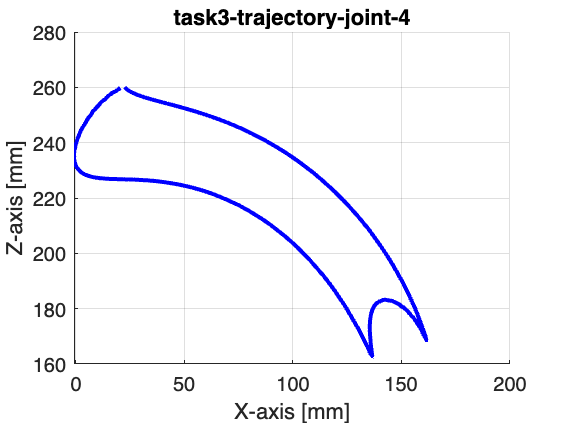

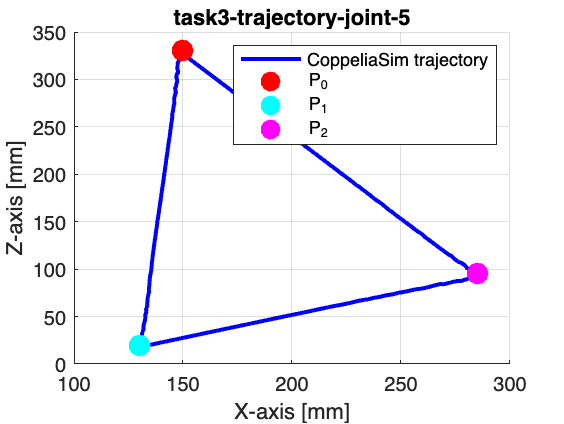

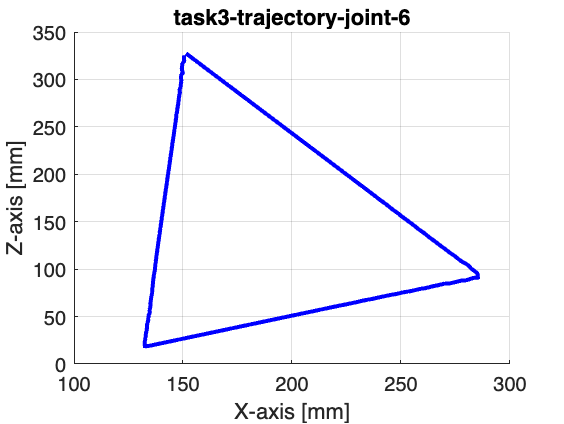


for i = 1:Num_joints
    plot_obj_trajectory_task_3(joint_positions(:, i, :), i == 5, foo + sprintf("joint-%d", i));
end

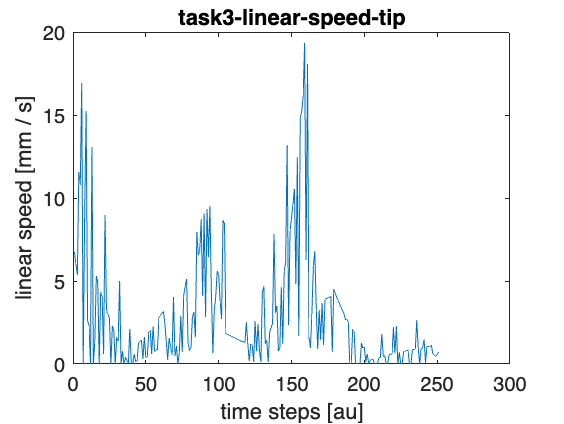


foo = "task3-linear-speed-";
plot_obj_linear_speed(tip_linear_speeds, foo + "tip");

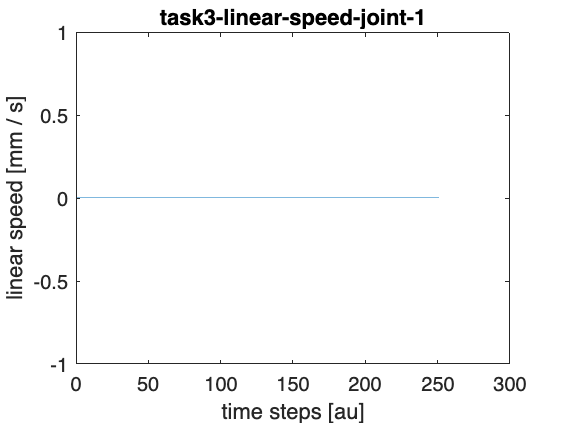

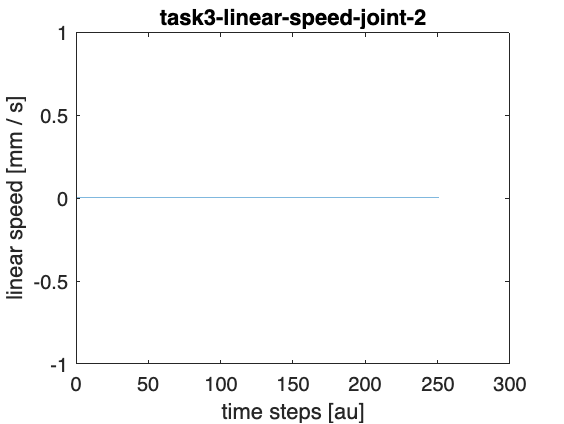

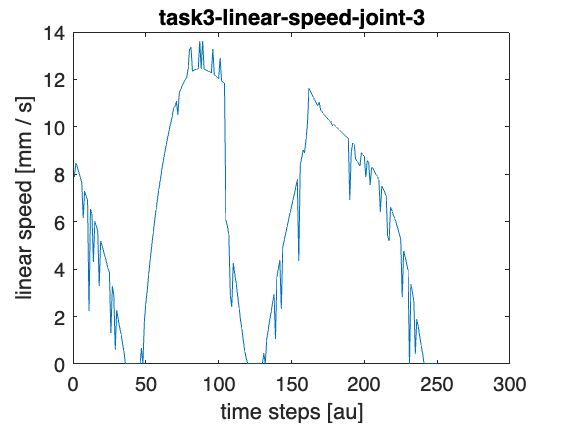

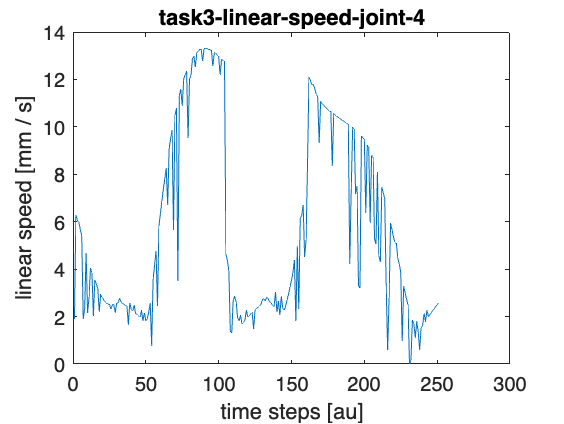

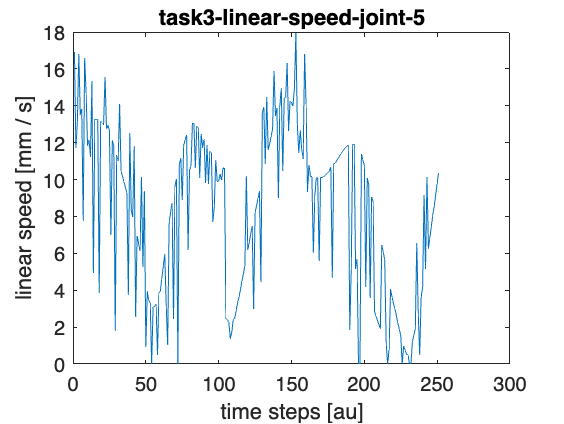

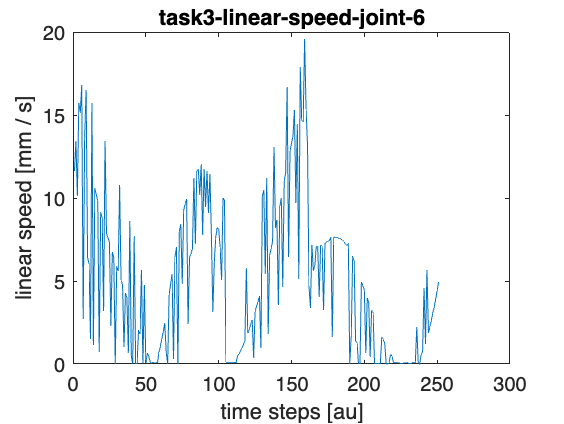

for i = 1:Num_joints
    plot_obj_linear_speed(squeeze(joint_linear_speeds(:, i)), foo + sprintf("joint-%d", i));
end 

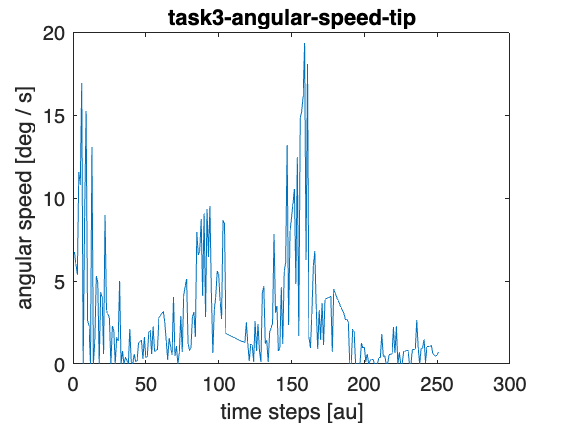


foo = "task3-angular-speed-";
plot_obj_angular_speed(tip_linear_speeds, foo + "tip");

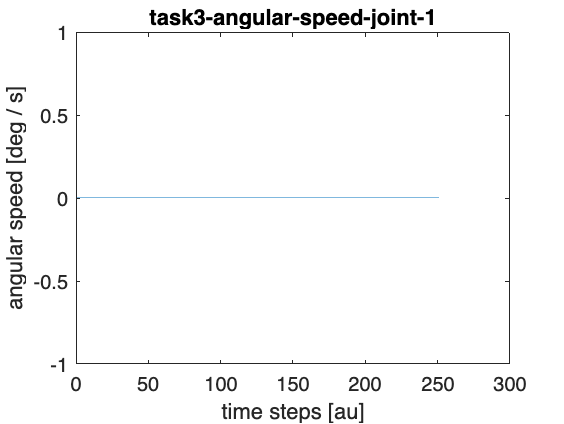

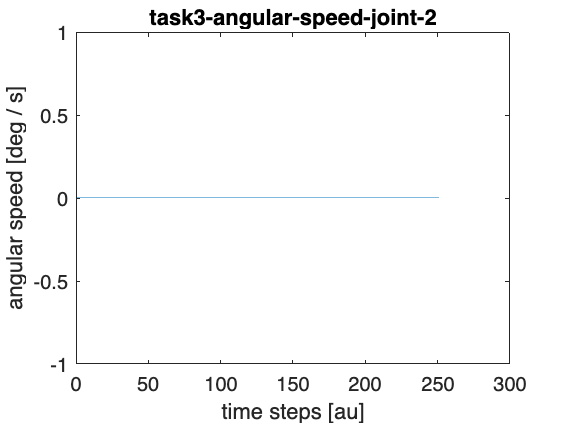

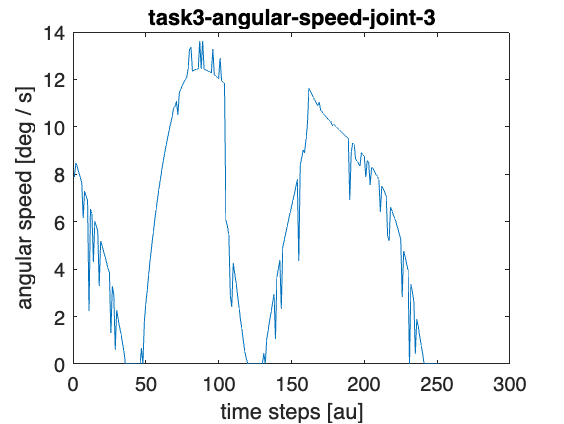

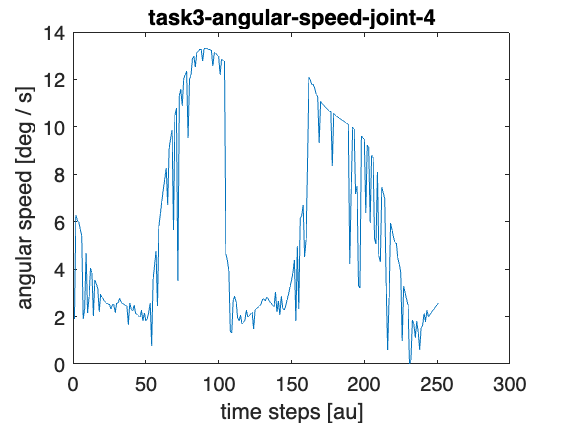

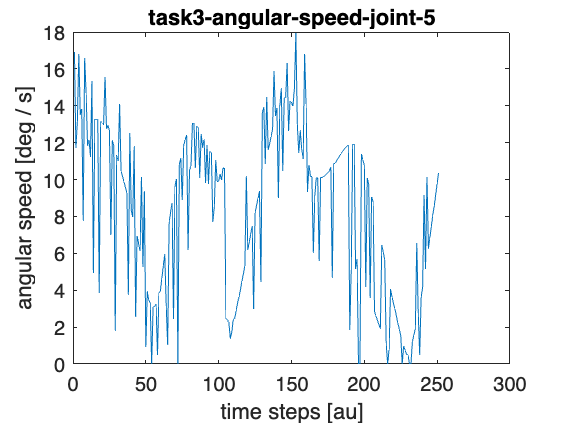

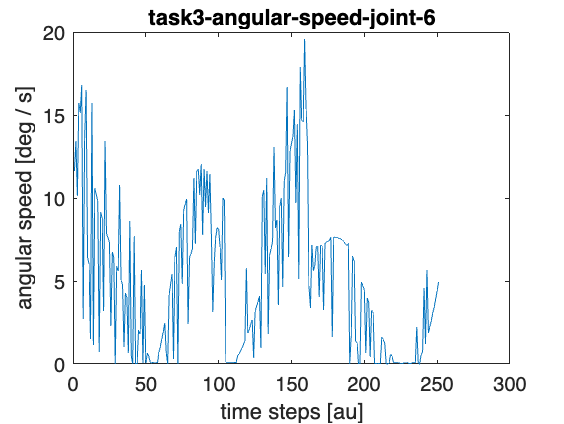

for i = 1:Num_joints
    plot_obj_angular_speed(squeeze(joint_linear_speeds(:, i)), foo + sprintf("joint-%d", i));
end 

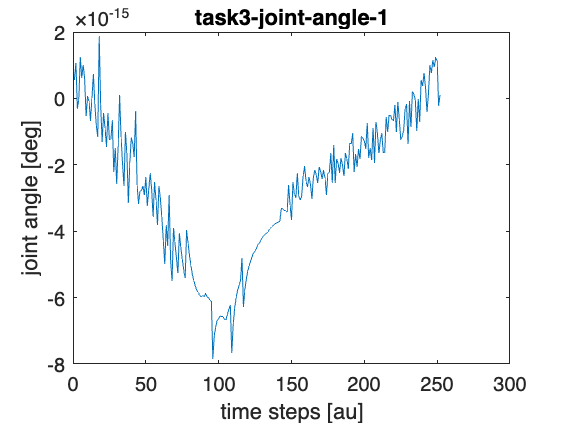

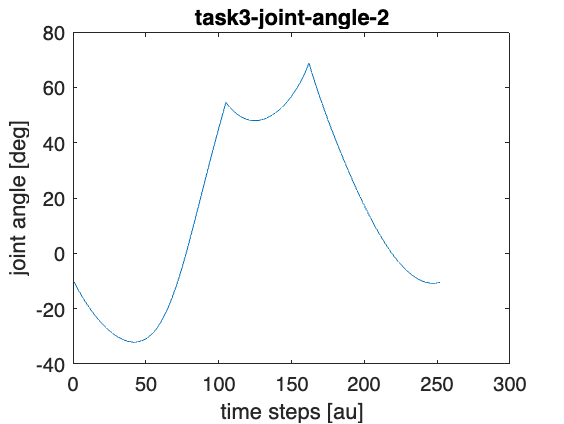

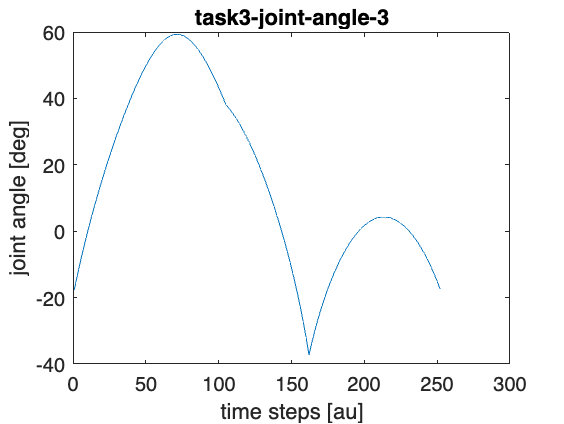

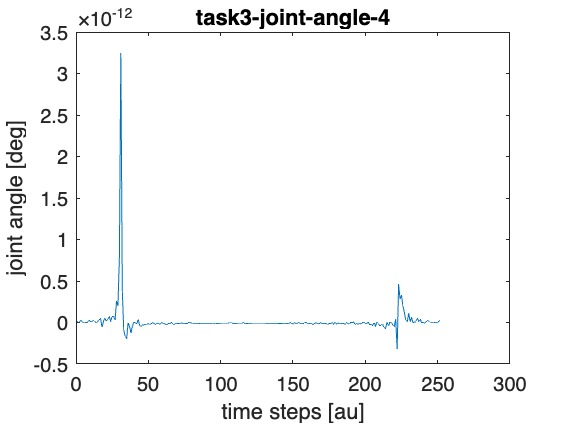

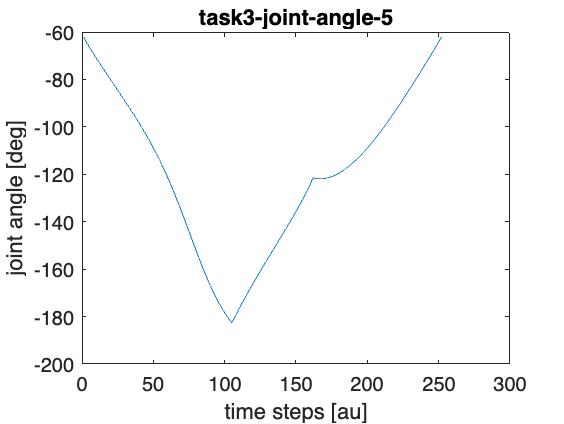

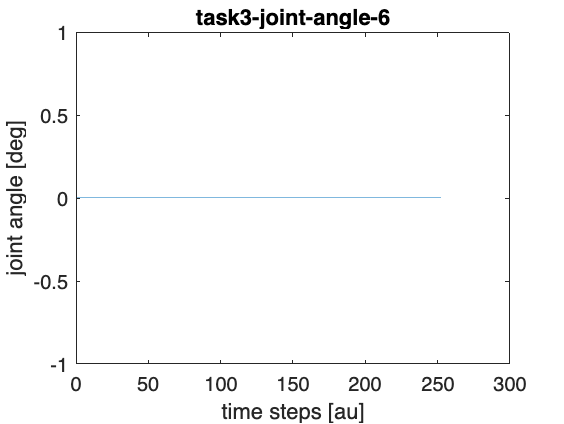


foo = "task3-joint-angle-";
for i = 1:Num_joints
    ys_deg = rad2deg(ys(:, i));
    fig_handle = figure;
    plot(ys_deg, "-");
    xlabel("time steps [au]");
    ylabel("joint angle [deg]");
    title(foo + i);
    filename = foo + sprintf("%d", i) + file_format;
    saveFigureAsPDF(fig_handle, filename);
    % saveas(gcf, filename);
end

mirobot = Mirobot_Matlab; 
s = mirobot.Mirobotconnect('/dev/tty.usbserial-14330'); %connect to /dev/tty.usbserial-10 for example
disp('Finish');
pause(2);

disp('Testing zeroing');
mirobot.go_to_zero(s); %return back to initial position
pause(2);

mirobot_xs = joint_angles;

disp('Testing joint control');
for i = 1:size(mirobot_xs, 1)
    angle_radians = squeeze(mirobot_xs(i, :));
    a = rad2deg(angle_radians);
    formatted_angles = cell(1, 6);
    
    % Loop through each element and store the formatted values
    for j = 1:6
        formatted_angles{j} = sprintf('%.2f', a(j));  % Format each angle
    end
    
    % If you want to access individual formatted values, you can use
    a1 = formatted_angles{1};
    a2 = formatted_angles{2};
    a3 = formatted_angles{3};
    a4 = formatted_angles{4};
    a5 = formatted_angles{5};
    a6 = formatted_angles{6};
    msg = mirobot.go_to_axis(s, a1, a2, a3, a4, a5, a6);
    if i == 1
        % 3 s
        pause(3);
    else
        % 50 ms
        pause(0.050);
    end
end

## Task 4

all_zeros = zeros(1, 6);
home_pos = fk(transformation_matrix_ee_sym, joint_angles_sym, all_zeros);
home_pos = home_pos';

cube_size = 20.0;
suction_shortening = 4.0;
xmas_tree_height = 134.96;
safe_z = xmas_tree_height + 1.5 * cube_size;
bot_branch_z = 40.0 + cube_size - suction_shortening;
top_branch_z = 70.0 + cube_size - suction_shortening;
xmas_tree_x = 250.5;

cube11_top = [xmas_tree_x 30 top_branch_z];
cube1temp_top = [xmas_tree_x -30 top_branch_z];
% should be -50 not -55
cube21_top = [xmas_tree_x -55 bot_branch_z];
% should be -40 not -55
cube12_top = [xmas_tree_x -55 bot_branch_z];
cube22_top = [xmas_tree_x 30 top_branch_z];

src = [
    cube11_top;
    cube21_top;
    cube1temp_top;
];
dst = [
    cube1temp_top;
    cube22_top;
    cube12_top;
];

segments = {};
[x1, y1, z1] = deal3(src(1, :));
harbour = home_pos;
for i = 1:size(src, 1)
    src_cur = src(i, :);
    dst_cur = dst(i, :);

    % approach: suction off
    [x1, y1, z1] = deal3(src_cur);
    segments{end+1} = [
        harbour;
        [x1, y1, safe_z];
        [x1, y1, z1];
    ];

    % move cube: suction on
    [x1, y1, z1] = deal3(src_cur);
    [x2, y2, z2] = deal3(dst_cur);
    segments{end+1} = [
        [x1, y1, z1];
        [x1, y1, safe_z];
        [x2, y2, safe_z];
        [x2, y2, z2];
    ];

    % go safe intro: suction off
    [x1, y1, z1] = deal3(dst_cur);
    segments{end+1} = [
        [x1, y1, z1];
        [x1, y1, z1 + 5.0];
    ];

    % go safe: suction off
    [x1, y1, z1] = deal3(dst_cur);
    harbour = [x1, y1, safe_z];
    segments{end+1} = [
        [x1, y1, z1 + 5.0];
        harbour;
    ];
end

[x1, y1, z1] = deal3(dst(end, :));
segments{end+1} = [
    [x1, y1, safe_z];
    [x1, y1 - cube_size, safe_z];
    [x1, y1 - cube_size, z1 - cube_size / 2];
    [x1, y1, z1 - cube_size / 2];
    [x1, y1, safe_z];
];

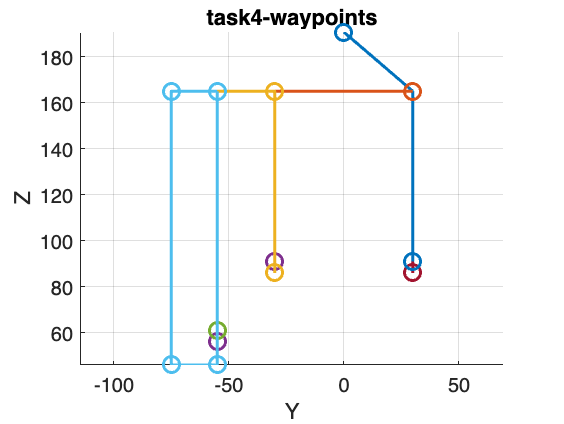

figure_handle = figure;
for i = 1:numel(segments)
% for i = 6:6
    foo = segments{i};
    % Assuming waypoints is a num_waypoints x 3 array
    % Extract X, Y, and Z coordinates
    X = foo(:, 1);
    Y = foo(:, 2);
    Z = foo(:, 3);
    hold on;
    % Plot the waypoints in 3D
    plot(Y, Z, '-o', 'LineWidth', 1.5, 'MarkerSize', 8);
    % for idx = 1:length(Y)
    %     text(Y(idx), Z(idx), sprintf('%d', idx), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
    % end
    hold off;
end

% Add labels and title
xlabel('Y');
ylabel('Z');
% zlabel('Z');
foo = "task4-waypoints";
title(foo);

% Enable grid and set equal scaling
grid on;
axis equal;
% axis([-(60 + 2 * small_dy) (60 + 2 * small_dy) 0 (safe_z + 10.0)]);

% Optionally, rotate the 3D view for better visualization
rotate3d on;
saveFigureAsPDF(figure_handle, foo + file_format);

interpolation_factor = 0.010;
angle_segments = {};
if false
    total = 0;
    tic;
    last_joint_angle_prev_segment = zeros(1, 6);
    for i = 1:numel(segments)
        xyz_spec_waypoints = segments{i} ./ 1000;
    
        foo = zeros(7, size(xyz_spec_waypoints, 1));
        for j = 1:size(xyz_spec_waypoints, 1)
            [x, y, z] = deal(xyz_spec_waypoints(j, 1), xyz_spec_waypoints(j, 2), xyz_spec_waypoints(j, 3));
            xyz = [x y z];
            quaternion = eul2quat([0 0 0]);
            foo(:, j) = cat(2, xyz, quaternion);
        end
        foo = interpolate_vectors(foo, interpolation_factor);
        % foo: num_waypoints x num_joints
        foo = foo';
        num_waypoints = size(foo, 1);
        disp(sprintf('%d / %d: %d\n', i, numel(segments), num_waypoints));
        total = total + num_waypoints;
        % continue;
    
        joint_angles = zeros(num_waypoints+1, num_joints);
        joint_angles(1, :) = last_joint_angle_prev_segment;
        for j = 1:num_waypoints
            waypoint = foo(j, :);
            previous_joint_angle_vector = joint_angles(j, :);
            joint_angles_res = calculate_angle_monolithic(joint_angles_sym, transformation_matrix_ee_sym, previous_joint_angle_vector, waypoint);
            joint_angles_res(1, 6) = 0.0;
            joint_angles(j+1, :) = joint_angles_res;
        end
        joint_angles = joint_angles(2:end, :);
        angle_segments{end+1} = joint_angles;
        last_joint_angle_prev_segment = joint_angles(end, :);
    end
    save('task_4_angle_segments.mat', 'angle_segments');
    clear angle_segments;
    elapsedTime = toc; % Stop the timer and get elapsed time
    minutes = floor(elapsedTime / 60); % Calculate whole minutes
    seconds = mod(elapsedTime, 60);    % Calculate remaining seconds
    
    fprintf('Time taken to execute the block: %d minutes and %.0f seconds\n', minutes, seconds);
    disp(total);
else
    loaded_data = load('task_4_angle_segments.mat');
    angle_segments = loaded_data.angle_segments;
end

sim.startSimulation();
xs = angle_segments;
total_waypoints = 0;
for i = 1:numel(xs)
    ys = xs{i};
    total_waypoints = total_waypoints + size(ys, 1);
end

tip_positions = zeros(total_waypoints,3);
tip_linear_speeds = zeros(1, total_waypoints);
tip_angular_speeds = zeros(1, total_waypoints);

joint_positions = zeros(total_waypoints, Num_joints, 3);
joint_linear_speeds = zeros(total_waypoints, Num_joints);
joint_angular_speeds = zeros(total_waypoints, Num_joints);

disp('Jogging the robot by directly setting joint position');

Jogging the robot by directly setting joint position


pause(5);
waypoint_ix = 0;
for i = 1:numel(xs)
    ys = xs{i};
    for j = 1:size(ys, 1)
        waypoint_ix = waypoint_ix + 1;
        for k = 1:Num_joints
            sim.setJointTargetPosition(Handles_joints(k), ys(j,k));
        end
        % sim.setObjectPosition(Handles_tip, -1, ys(j, :));
        % sim.setObjectOrientation(Handles_tip, -1, [0 0 0]);

        for k = 1:Num_joints
            joint_pose_array = sim.getObjectPosition(Handles_joints(k));
            joint_positions(waypoint_ix, k, 1:3) = [joint_pose_array{1:3}];
            [linear_velocity, angular_velocity] = sim.getObjectVelocity(Handles_joints(k));
            joint_linear_speeds(waypoint_ix, k) = sqrt(sum([linear_velocity{1:3}].^2, 2));
            joint_angular_speeds(waypoint_ix, k) = sqrt(sum([[angular_velocity{1:3}]].^2, 2));
        end
        Tip_pose_array = sim.getObjectPosition(Handles_tip);
        tip_positions(waypoint_ix, 1:3) = [Tip_pose_array{1:3}];
        [linear_velocity, angular_velocity] = sim.getObjectVelocity(Handles_tip);
        tip_linear_speeds(waypoint_ix) = sqrt(sum([linear_velocity{1:3}].^2, 2));
        tip_angular_speeds(waypoint_ix) = sqrt(sum([[angular_velocity{1:3}]].^2, 2));

        if j == 1
            if i == 1
                sim.wait(3.000);
            % else
            %     sim.wait(1.500);
            end
        % else
        %     sim.wait(0.500);
        end
    end
end

disp('End jogging');

End jogging


pause(2);
% sim.setObjectInt32Parameter(Handles_tip, sim.objintparam_dynamic, 1);
sim.stopSimulation();
fprintf('Program ended\n');

Program ended


disp(total_waypoints);

   182



disp(waypoint_ix);

   182




tip_positions = tip_positions(2:end, :);
tip_linear_speeds = tip_linear_speeds(:, 2:end);
tip_angular_speeds = tip_angular_speeds(:, 2:end);

joint_positions = joint_positions(2:end, :, :);
joint_linear_speeds = joint_linear_speeds(2:end, :);
joint_angular_speeds = joint_angular_speeds(2:end, :);

tip_positions = tip_positions .* 1000;
tip_linear_speeds = tip_linear_speeds .* 1000;
tip_angular_speeds = rad2deg(tip_angular_speeds);

joint_positions = joint_positions .* 1000;
joint_linear_speeds = joint_linear_speeds .* 1000;
joint_angular_speeds = rad2deg(joint_angular_speeds);

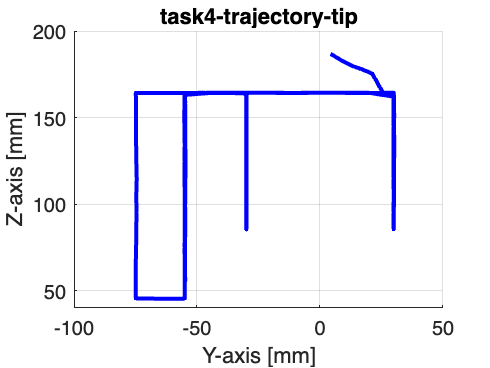

foo = "task4-trajectory-";
plot_obj_trajectory_task_4(tip_positions, foo + "tip");

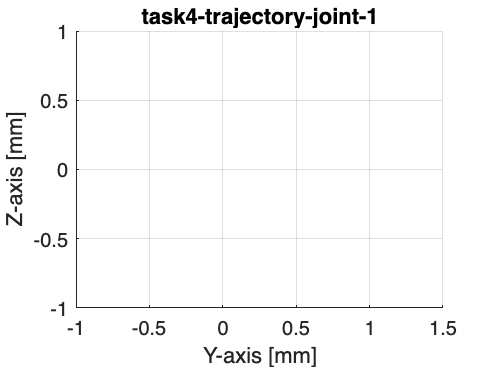

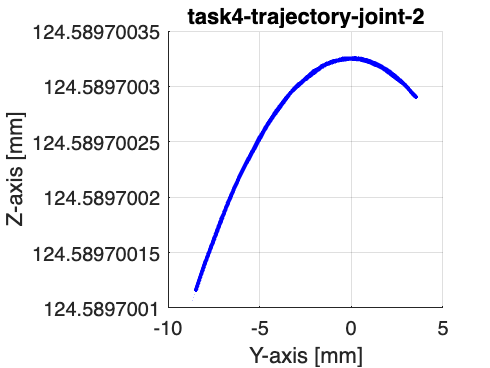

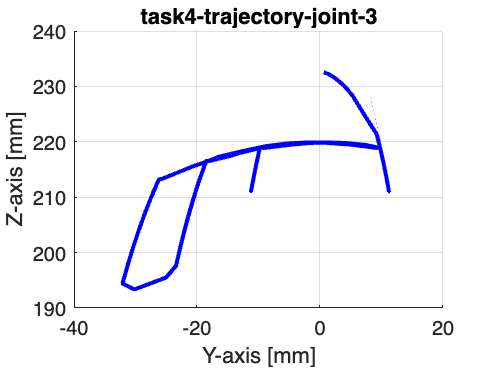

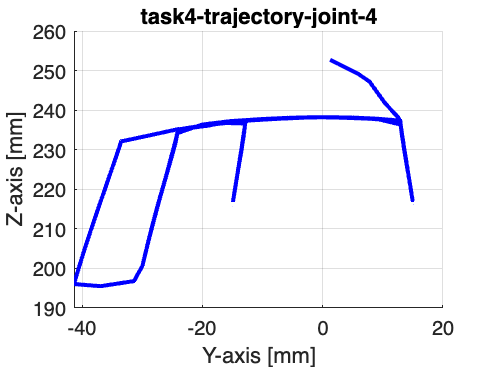

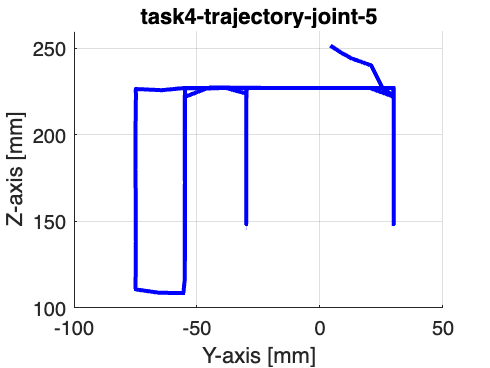

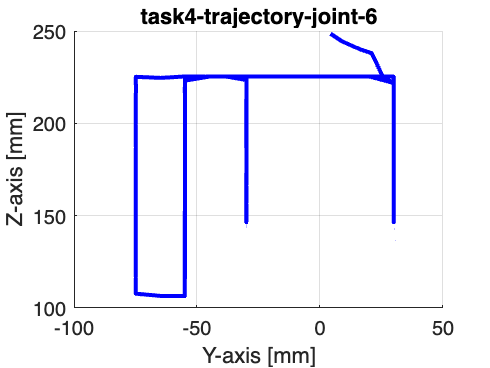


for i = 1:Num_joints
    plot_obj_trajectory_task_4(joint_positions(:, i, :), foo + sprintf("joint-%d", i));
end

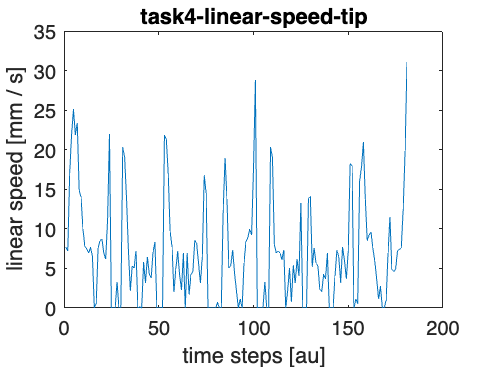


foo = "task4-linear-speed-";
plot_obj_linear_speed(tip_linear_speeds, foo + "tip");

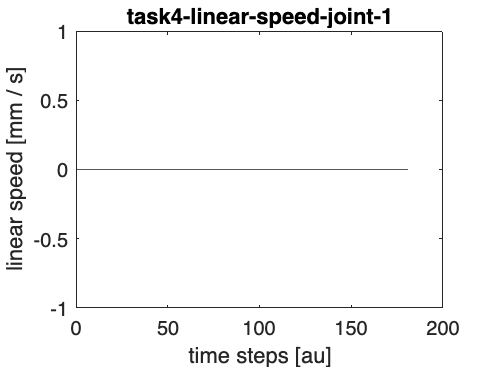

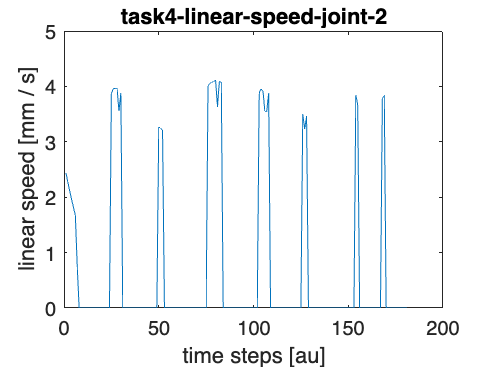

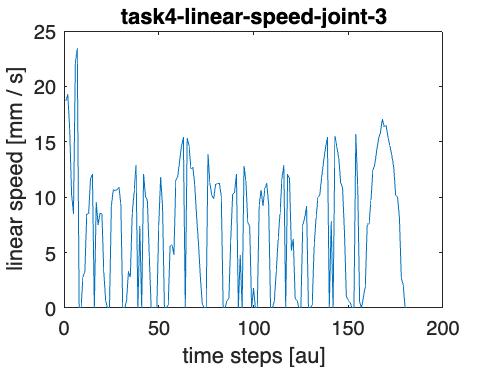

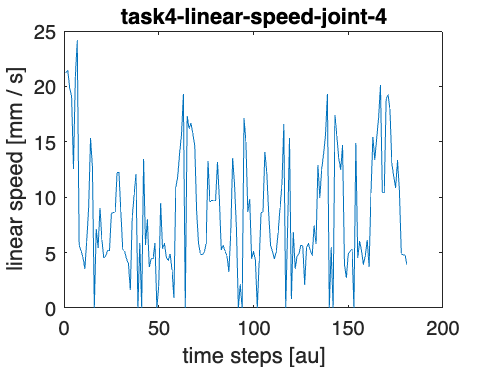

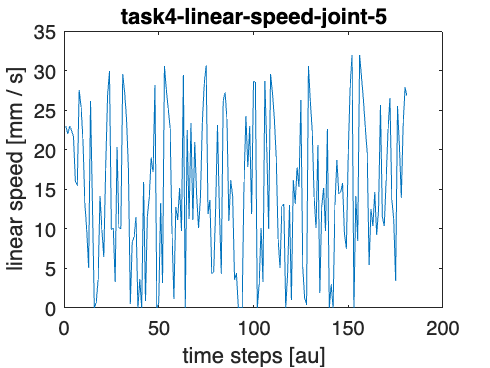

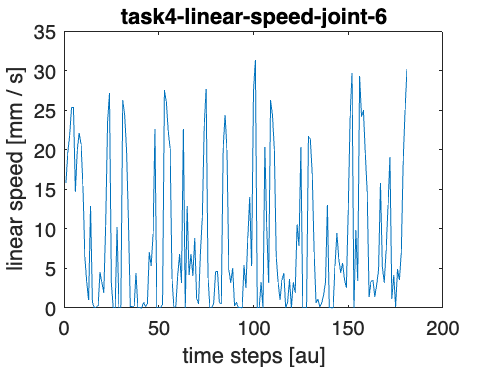

for i = 1:Num_joints
    plot_obj_linear_speed(squeeze(joint_linear_speeds(:, i)), foo + sprintf("joint-%d", i));
end 

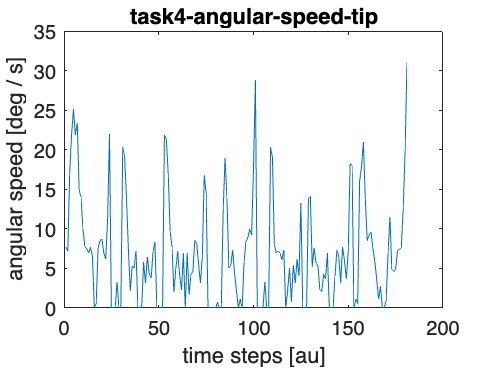


foo = "task4-angular-speed-";
plot_obj_angular_speed(tip_linear_speeds, foo + "tip");

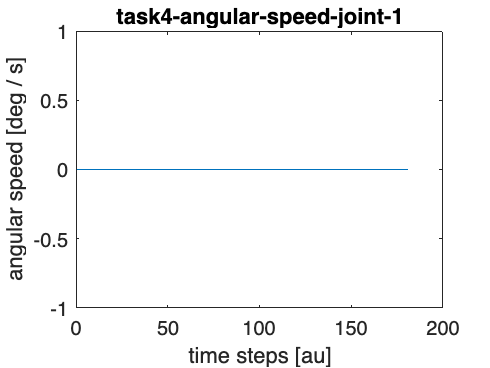

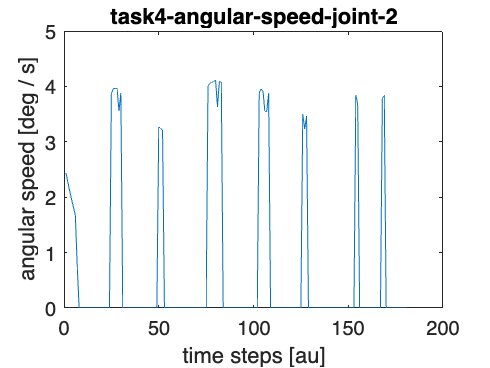

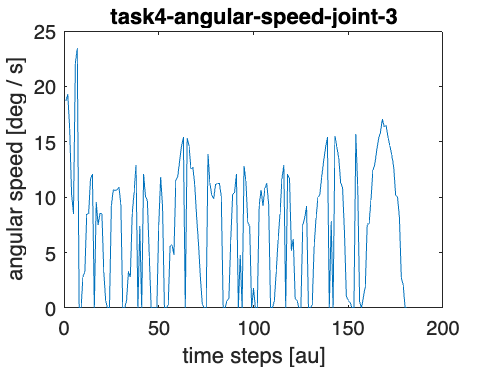

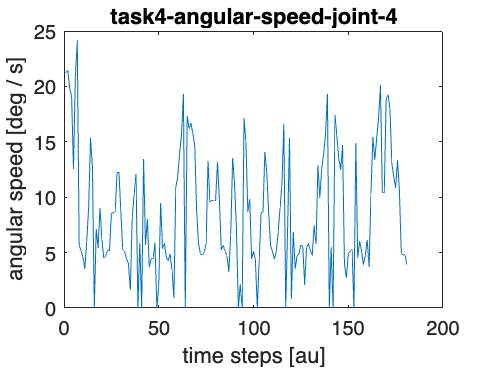

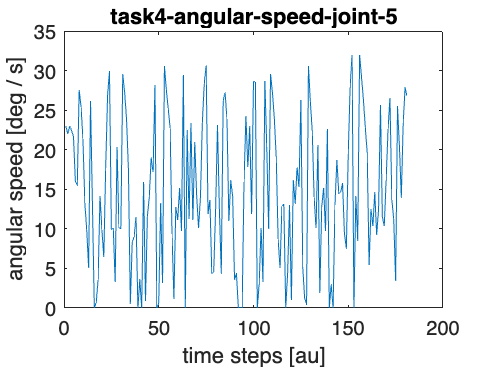

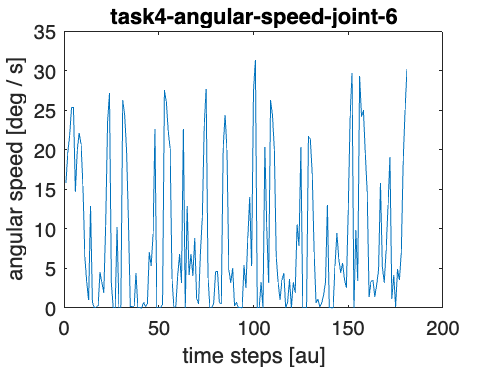

for i = 1:Num_joints
    plot_obj_angular_speed(squeeze(joint_linear_speeds(:, i)), foo + sprintf("joint-%d", i));
end 

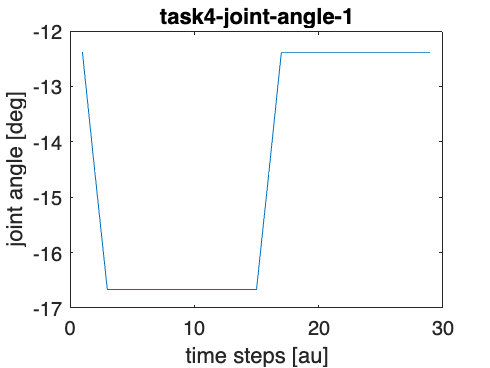

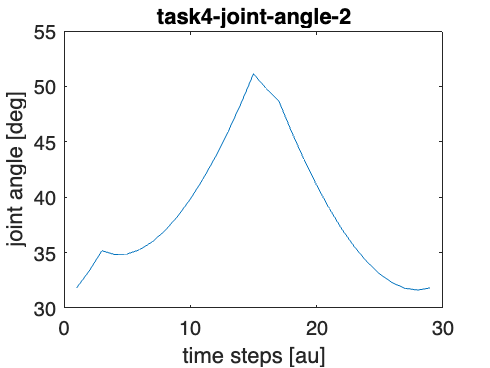

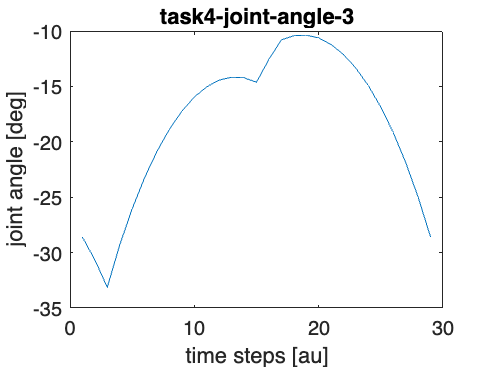

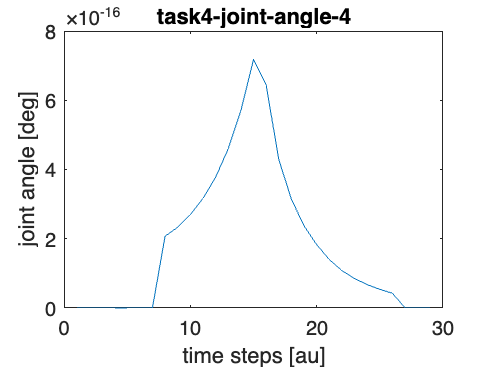

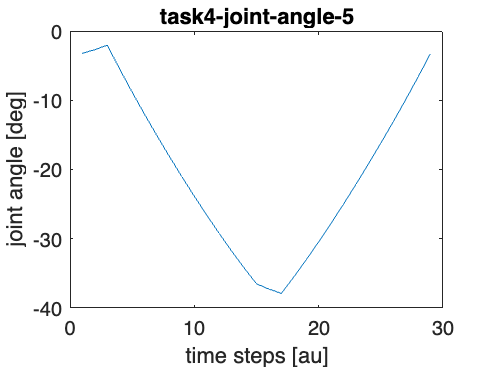

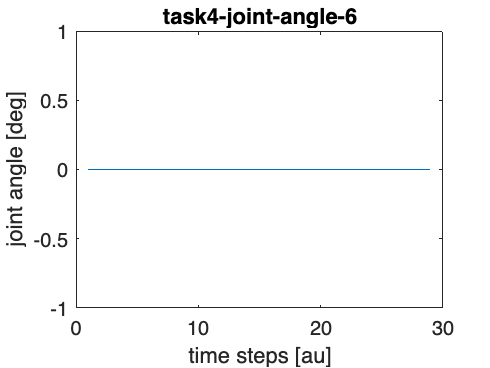


foo = "task4-joint-angle-";
for i = 1:Num_joints
    ys_deg = rad2deg(ys(:, i));
    figure;
    plot(ys_deg, "-");
    xlabel("time steps [au]");
    ylabel("joint angle [deg]");
    title(foo + i);
    saveFigureAsPDF(gcf, foo + i + file_format);
end

mirobot = Mirobot_Matlab; 
s = mirobot.Mirobotconnect('/dev/tty.usbserial-14330');

mirobot.go_to_zero(s); %return back to initial position
pause(2);

% initial mirobot control loop used for testing, set cartesion positions
% directly

% off on off off
% 1 2 3 0
offset = [4 -3 40];
for i = 1:numel(segments)
% for i = 1:3
    foo = mod(i, 4);
    if foo == 0
        foo = 4;
    end
    if foo == 1 || foo == 3 || foo == 4
        mirobot.suction_off(s);
        pause(1);
    elseif foo == 2
        mirobot.suction_on(s);
        pause(3);
    else
        error('should not happen!');
    end

    mirobot_xs = segments{i};
    for j = 1:size(mirobot_xs, 1)
        xyz = squeeze(mirobot_xs(j, :));
        xyz = xyz + offset;

        formatted_coords = cell(1, 3);
        
        for k = 1:3
            formatted_coords{k} = sprintf('%.2f', xyz(k));  % Format each coord
        end

        x = formatted_coords{1};
        y = formatted_coords{2};
        z = formatted_coords{3};

        msg = mirobot.go_to_cartesian_lin(s, x, y, z, 0, 0, 0);
        if j == 1
            if i == 1
                % 3 s
                pause(3);
            else
                % 1 s
                pause(0.050);
            end
        else
            % 50 ms
            pause(0.050);
        end
    end
    disp(i);
end

% once waypoints have been tested in previous loop, run the mirobot using
% joint angles computed using inverse kinematics

for i = 1:numel(angle_segments)
% for i = 1:2
    if mod(i, 2) == 1
        mirobot.suction_off(s);
        pause(2);
    else
        mirobot.suction_on(s);
        pause(2);
    end
    mirobot_xs = angle_segments{i};
    for j = 1:size(mirobot_xs, 1)
        angle_radians = squeeze(mirobot_xs(j, :));
        a = rad2deg(angle_radians);
        formatted_angles = cell(1, 6);
        
        % Loop through each element and store the formatted values
        for k = 1:6
            formatted_angles{k} = sprintf('%.2f', a(k));  % Format each angle
        end
        
        % If you want to access individual formatted values, you can use
        a1 = formatted_angles{1};
        a2 = formatted_angles{2};
        a3 = formatted_angles{3};
        a4 = formatted_angles{4};
        a5 = formatted_angles{5};
        a6 = formatted_angles{6};
        msg = mirobot.go_to_axis(s, a1, a2, a3, a4, a5, a6);
        if j == 1
            if i == 1
                % 3 s
                pause(3);
            else
                % 1 s
                pause(0.050);
            end
        else
            % 50 ms
            pause(0.050);
        end
    end
end

% just for testing and calibrating the mirobot when in cartesian mode

xyz = [250 0 0];
offset = [4 -2 40];
xyz = xyz + offset;

formatted_coords = cell(1, 3);

for k = 1:3
    formatted_coords{k} = sprintf('%.2f', xyz(k));  % Format each coord
end

x = formatted_coords{1};
y = formatted_coords{2};
z = formatted_coords{3};

msg = mirobot.go_to_cartesian_lin(s, x, y, z, 0, 0, 0);

## Bonus task

h1 = 45;         % x-coordinate of the center
k1 = 125;         % y-coordinate of the center
r1 = 35;         % radius of the circle

theta = [30, 150, -90];    % angle in degrees (measured from x+ axis)
theta_rad = deg2rad(theta);
downwards_traingle_x = h1 + r1 * cos(theta_rad);
downwards_traingle_y = k1 + r1 * sin(theta_rad);

theta = [90, -30, -150];    % angle in degrees (measured from x+ axis)
theta_rad = deg2rad(theta);
upwards_traingle_x = h1 + r1 * cos(theta_rad);
upwards_traingle_y = k1 + r1 * sin(theta_rad);

h2 = 115;
k2 = 125;
r2 = 35;
theta = [-150, 90, -30];    % angle in degrees (measured from x+ axis)
theta_rad = deg2rad(theta);
A_triangle_x = h2 + r2 * cos(theta_rad);
A_triangle_y = k2 + r2 * sin(theta_rad);

x1 = A_triangle_x(3); y1 = A_triangle_y(3); % Point A
x2 = A_triangle_x(2); y2 = A_triangle_y(2); % Point B
m = 1;
n = 2;
A_triangle_h_bar_x1 = (m * x2 + n * x1) / (m + n);
A_triangle_h_bar_y1 = (m * y2 + n * y1) / (m + n);

x1 = A_triangle_x(1); y1 = A_triangle_y(1); % Point A
x2 = A_triangle_x(2); y2 = A_triangle_y(2); % Point B
m = 1;
n = 2;
A_triangle_h_bar_x2 = (m * x2 + n * x1) / (m + n);
A_triangle_h_bar_y2 = (m * y2 + n * y1) / (m + n);

h3 = 185;  % x-coordinate of the center
k3 = 125;  % y-coordinate of the center
r3 = 35;  % radius of the circle

num_points_c = 10;
theta1 = linspace(pi/4, pi, num_points_c / 2);   % from 45 degrees to 180 degrees
theta2 = linspace(-pi, -pi/4, num_points_c / 2); % from -180 degrees to -45 degrees
theta = [theta1, theta2];          % combine both ranges

c_x = h3 + r3 * cos(theta);
c_y = k3 + r3 * sin(theta);

h4 = 255;  % x-coordinate of the center
k4 = 125;  % y-coordinate of the center
r4 = 35;  % radius of the circle
p4 = 35;

e_mid_left_x = h4 - p4;
e_mid_left_y = k4;

e_top_left_x = h4 - p4;
e_top_left_y = k4 + r4;

e_bot_left_x = h4 - p4;
e_bot_left_y = k4 - r4;

e_mid_right_x = h4 + r4;
e_mid_right_y = k4;

e_top_right_x = h4 + r4;
e_top_right_y = k4 + r4;

e_bot_right_x = h4 + r4;
e_bot_right_y = k4 - r4;

xs1 = [
    downwards_traingle_x...
    upwards_traingle_x...
    A_triangle_x...
    A_triangle_h_bar_x1...
    A_triangle_h_bar_x2...
    c_x...
    e_top_right_x...
    e_top_left_x...
    e_mid_left_x...
    e_mid_right_x...
    e_bot_left_x...  
    e_bot_right_x...
];

ys1 = [
    downwards_traingle_y...
    upwards_traingle_y...
    A_triangle_y...
    A_triangle_h_bar_y1...
    A_triangle_h_bar_y2...
    c_y...
    e_top_right_y...
    e_top_left_y...
    e_mid_left_y...
    e_mid_right_y...
    e_bot_left_y...  
    e_bot_right_y...
];

figure;
scatter(xs1, ys1, 'filled'); % 'filled' makes the markers solid
xlabel('x-axis');          % Label for the x-axis
ylabel('y-axis');          % Label for the y-axis
title('Scatter Plot of xs vs ys'); % Title for the plot
grid on;                   % Add a grid for better readability
axis([0 300 0 200]);

[xs2, ys2, zs2] = get_bonus_task_coords(xs1, ys1);
waypoints = cat(1, xs2, ys2, zs2);
waypoints = waypoints';
waypoints = waypoints ./ 1000;

segments = {};
foo = cat(1, waypoints(1:3, :), waypoints(1, :));
segments{end+1} = foo;
foo = cat(1, waypoints(4:6, :), waypoints(4, :));
segments{end+1} = foo;
foo = waypoints(7:11, :);
segments{end+1} = foo;
foo = waypoints(12:12+size(c_x, 2)-1, :);
segments{end+1} = foo;
ei = 12+size(c_x, 2);
foo = cat(1, waypoints(ei:ei+3, :), waypoints(ei+2, :), waypoints(ei+4:ei+5, :));
segments{end+1} = foo;

for i = 1:numel(segments)
    foo = segments{i};
    segments{i} = add_lift(foo);
end

figure;
for i = 1:numel(segments)
    foo = segments{i};
    % Assuming waypoints is a num_waypoints x 3 array
    % Extract X, Y, and Z coordinates
    X = foo(:, 1);
    Y = foo(:, 2);
    Z = foo(:, 3);
    hold on;
    % Plot the waypoints in 3D
    plot3(X, Y, Z, '-o', 'LineWidth', 1.5, 'MarkerSize', 8);
    hold off;
end

% Add labels and title
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D Waypoints Plot');

% Enable grid and set equal scaling
grid on;
axis equal;

% Optionally, rotate the 3D view for better visualization
rotate3d on;

interpolation_factor = 0.010;
angle_segments = {};
if false
    last_joint_angle_prev_segment = zeros(1, 6);
    for i = 1:numel(segments)
    % for i = 1:1
        xyz_spec_waypoints = segments{i};
    
        foo = zeros(7, size(xyz_spec_waypoints, 1));
        for j = 1:size(xyz_spec_waypoints, 1)
            [x, y, z] = deal(xyz_spec_waypoints(j, 1), xyz_spec_waypoints(j, 2), xyz_spec_waypoints(j, 3));
            xyz = [x y z];
            quaternion = eul2quat([0 -pi/12 0]);
            foo(:, j) = cat(2, xyz, quaternion);
        end
        foo = interpolate_vectors(foo, interpolation_factor);
        % foo: num_waypoints x num_pose_dims
        foo = foo';
        num_waypoints = size(foo, 1);
    
        joint_angles = zeros(num_waypoints+1, num_joints);
        joint_angles(1, :) = last_joint_angle_prev_segment;
        disp(num_waypoints);
        for j = 1:num_waypoints
            waypoint = foo(j, :);
            previous_joint_angle_vector = joint_angles(j, :);
            joint_angles_res = calculate_angle_monolithic(joint_angles_sym, transformation_matrix_ee_sym, previous_joint_angle_vector, waypoint);
            joint_angles_res(1, 6) = 0.0;
            joint_angles(j+1, :) = joint_angles_res;
            disp(j);
        end
        joint_angles = joint_angles(2:end, :);
        angle_segments{end+1} = joint_angles;
        last_joint_angle_prev_segment = joint_angles(end, :);
    end
    save('bonus_task_angle_segments.mat', 'angle_segments');
    clear angle_segments;
else
    loaded_data = load('bonus_task_angle_segments.mat');
    angle_segments = loaded_data.angle_segments;
end

sim.startSimulation();
disp('Jogging the robot by directly setting joint position');
for i = 1:numel(angle_segments)
    ys = angle_segments{i};
    for j = 1:size(ys, 1)
        for k = 1:Num_joints
            sim.setJointTargetPosition(Handles_joints(k), ys(j,k));
        end
        if j == 1
            if i == 1
                sim.wait(3.000);
            else
                sim.wait(1.500);
            end
        else
            sim.wait(0.500);
        end
    end    
end
disp('End jogging');
pause(2);
fprintf('Program ended\n');
sim.stopSimulation();

for i = 1:numel(angle_segments)
    mirobot_xs = angle_segments{i};
    for j = 1:size(mirobot_xs, 1)
        angle_radians = squeeze(mirobot_xs(j, :));
        a = rad2deg(angle_radians);
        formatted_angles = cell(1, 6);
        
        % Loop through each element and store the formatted values
        for k = 1:6
            formatted_angles{k} = sprintf('%.2f', a(k));  % Format each angle
        end
        
        % If you want to access individual formatted values, you can use
        a1 = formatted_angles{1};
        a2 = formatted_angles{2};
        a3 = formatted_angles{3};
        a4 = formatted_angles{4};
        a5 = formatted_angles{5};
        a6 = formatted_angles{6};
        msg = mirobot.go_to_axis(s, a1, a2, a3, a4, a5, a6);
        if j == 1
            if i == 1
                % 3 s
                pause(3);
            else
                % 1 s
                pause(1);
            end
        else
            % 50 ms
            pause(0.050);
        end
    end
end
mirobot.go_to_zero(s); %return back to initial position
pause(2);

mirobot.go_to_zero(s); %return back to initial position
pause(2);